# Overview and Motivation

*This example uses a fictional scenario based on a typical engineer's experience for the purpose of demonstration. Any use of names of actual products or firms is entirely coincidental and unintentional. The contents of this example do not constitute a real design.*

*This example was created using MATLAB*®* R2022a.*

*Copyright 2022 The MathWorks, Inc.*

You are an engineer at ***Farnswerth Automotive*** and are on a secret project team developing a single-occupant [Level 5 autonomous vehicle](https://en.wikipedia.org/wiki/Automated_driving_system#Level_5_%E2%80%93_Full_automation), which many call **The Pod**.

Your team, which designs the control system software, is about to complete the "desktop simulation" phase of the project before moving on to the much-anticipated "hardware in the loop" testing phase in the brand new **state-of-the-art** testing facility hidden away from the rest of the company. Everyone is excited!

One of your team's responsibilities is the adaptive cruise control feature, which should set **The Pod** apart from its competition because it will allow multiple Pods to travel within 1 meter of each other at 100 km/h. Your CEO has been posting about this specific feature on social media for months now.

You have been tasked with testing a colleague's design of the Target Speed Selection algorithm, which calculates the vehicle's target speed to be used elsewhere in the adaptive cruise control logic. Your responsibilities are to ensure that the algorithm was implemented correctly according to its requirements and to ensure that it it is completely tested.

In this example workflow, we will be using the following MathWorks products to accomplish these goals:

[**Requirements Toolbox™**](https://www.mathworks.com/products/requirements-toolbox.html) to manage requirements in the Simulink environment

[**Simulink® Test™**](https://www.mathworks.com/products/simulink-test.html) to develop, manage, and execute simulation-based tests

[**Simulink® Coverage™**](https://www.mathworks.com/products/simulink-coverage.html) to measure test completeness

[**Simulink® Design Verifier™**](https://www.mathworks.com/products/simulink-design-verifier.html) to generate test vectors to analyze missing model test coverage

This example assumes that the user has a basic knowledge of [**Simulink®**](https://www.mathworks.com/products/simulink.html) and [**Stateflow®**](https://www.mathworks.com/products/stateflow.html).

# Part 1: Create a Test and Link to Requirements

In Part 1 of the workflow, we will create one test for one requirement. In Part 2, we will run a full test suite, which will test several requirements.

The goals for this part are to learn how to:

- create a test harness

- create a temporal assessment to define pass/fail criteria

- create a test case using the harness and the assessment

- link the test case to the requirement

- execute the created test case to determine whether the test passed

Here are the products we will use in Part 1:

**Requirements Toolbox™ **is used to view and author requirements within MATLAB® and Simulink®, as well as to establish traceability between requirements, Simulink® models, MATLAB® code, and test cases to understand the impact of a change in requirements.

**Simulink® Test™** is used to create, manage, and execute test cases for simulation-based testing in Simulink®. You can use Simulink® Test™ to create test harnesses, create test vectors using a variety of methods such as a test sequence, create test assessments to determine pass/fail criteria, and link test cases to requirements.

We will use other features of Simulink® Test™ in Part 2 of the workflow.

## Step 1: View the Requirement Being Tested

**Requirements Toolbox™ ** includes the Requirements Editor, which is a stand-alone tool (separate from a model) which can be used to import, author, and manage requirements as well as manage requirements traceability. Requirements can be imported from tools such as Microsoft Word, Microsoft Excel, IBM Rational DOORS, ReqIF files, and more.

In this part of the example, we will be working with requirements that have already been imported into Requirements Toolbox™.

Requirements are stored as "requirements sets", which have a file extension of **.slreqx**.

Requirements links are stored as "link sets", which have a file extension of **.slmx**.

Let's open the requirements for the Target Speed Selection algorithm. These are contained in the Cruise Control requirements set.

To open the Cruise Control requirements in the Requirements Editor, run the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

slreq.open('CruiseControl');

The requirement you will be testing has ID #34. It is located in Section 3 of the requirements set.

**"The cruise control system shall transition to disengaged from engaged within 0.25 seconds after a braking event has occurred."**

You can use the following command to open the Requirements Editor directly to that requirement:

rmi.navigate('linktype_rmi_slreq','CruiseControl.slreqx','34')

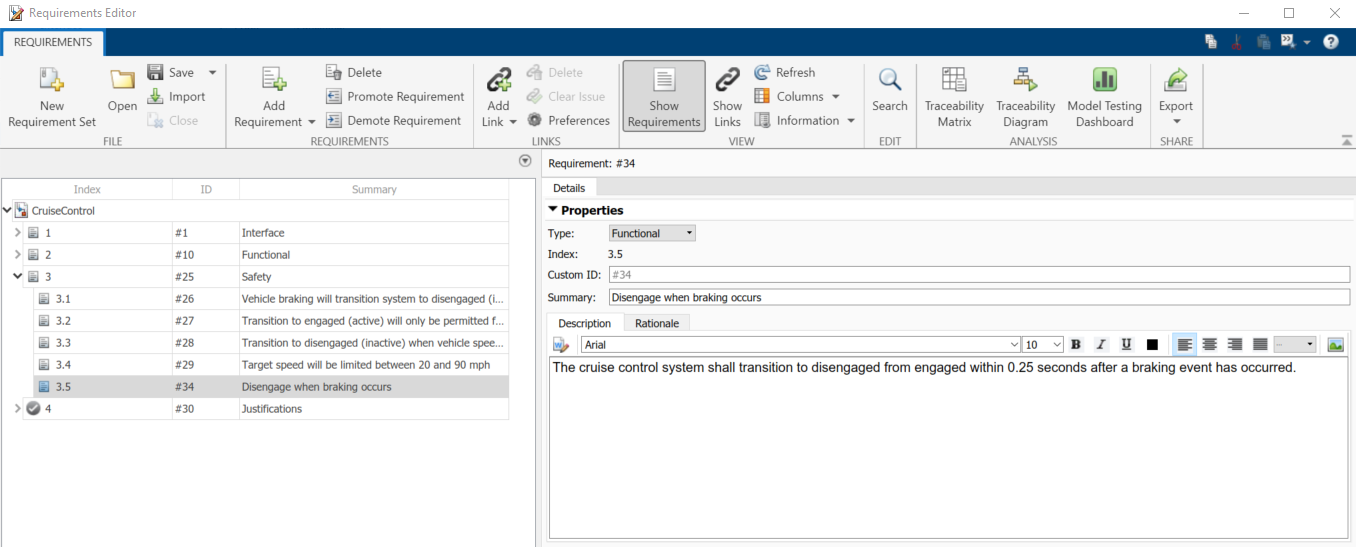

To learn more about how to programmatically work with requirements, please refer to [the documentation](https://www.mathworks.com/help/slrequirements/referencelist.html).

## Step 2: Create a test harness

Test harnesses are independent Simulink® models used to isolate the component under test to verify design models without modifying the design itself. With Simulink® Test™, you can create test harnesses which are automatically associated with a design model. A design model can have several test harnesses.

For this example, we will save the test harness externally from the design model as a separate file. This is done in order to keep track of the testing files separately from the design files. 

Here are the steps to take:

1) Open the Target Speed Selection model by running the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

open_system('CruiseControl')

2) Open the Simulink® Test™ app via the Simulink® Toolstrip. The Simulink® Test™ app is available under the APPS tab.

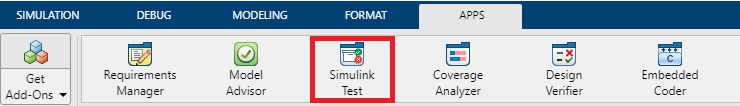

3) Click on the **Add Test Harness **button in the Simulink® Test™ app toolstrip. Make sure "CruiseControl" is shown in the text area for "Create Test Harness for". This will create a harness for the CruiseControl model and not the state chart. If you see "Compute target speed", change the slection to the CruiseControl model by clicking any empty area on the Simulink canvas.

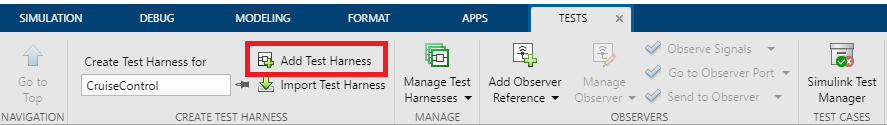

You will then see the **Create Test Harness** window.

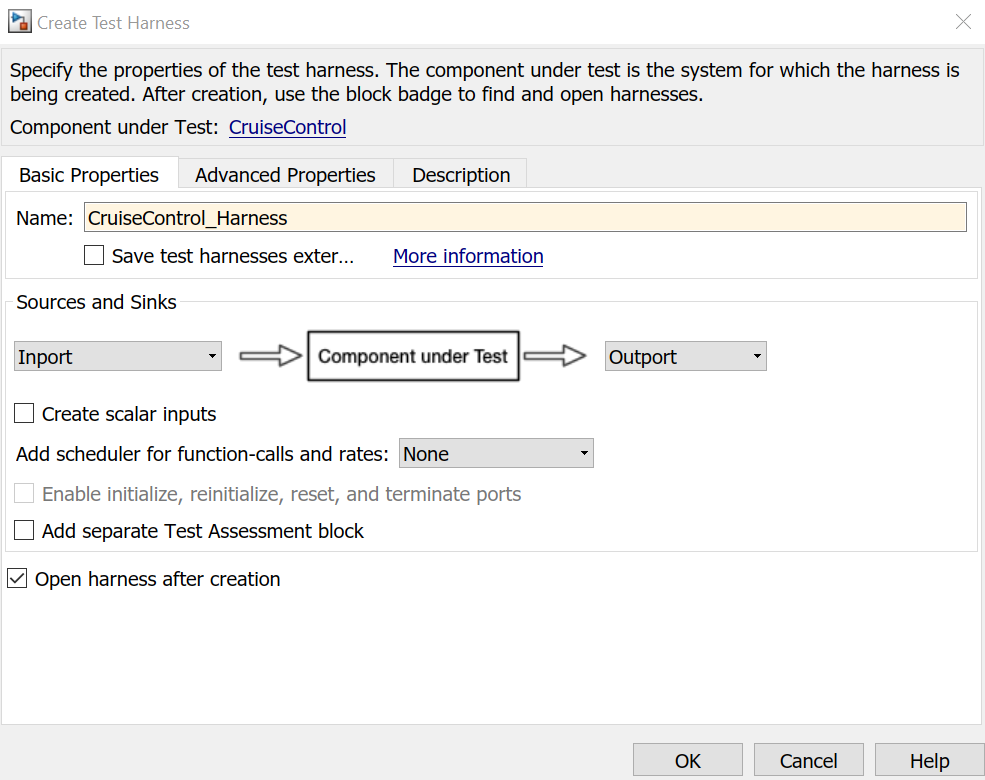

4) Name the test harness **CruiseControl_Harness**.

5) Under Sources and Sinks, click on the input dropdown ("Inport" should be selected by default), and select **Test Sequence**. For more information on other options for Sources, please refer to the [Simulink Test Inputs documentation](https://www.mathworks.com/help/sltest/inputs.html).

6) Select "Save test harnesses externally". This will create a separate model file called **CruiseControl_Harness.slx** which we can use for testing. The test harness we will create will remain in sync with the design model, similar to how a [Model Reference](https://www.mathworks.com/help/simulink/ug/overview-of-model-referencing-1.html) works.

7) In the **Advanced Properties** tab, select "Log output signals"

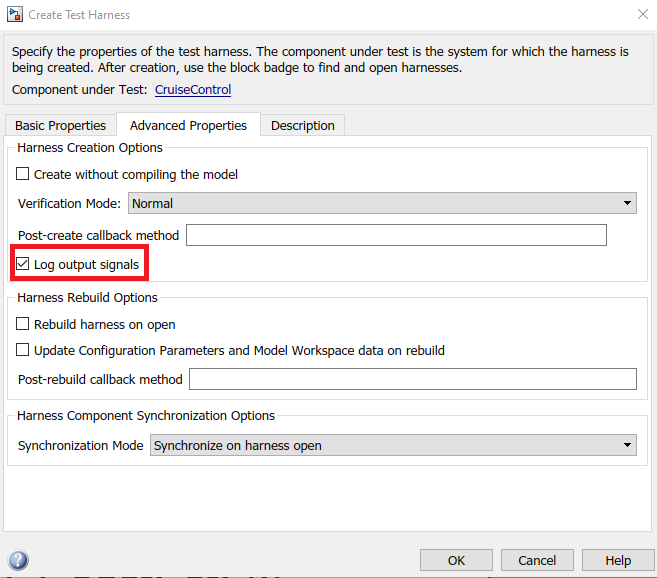

8) Save the harness in the Tests/Harnesses directory

9) Make sure "Open harness after creation" is selected.

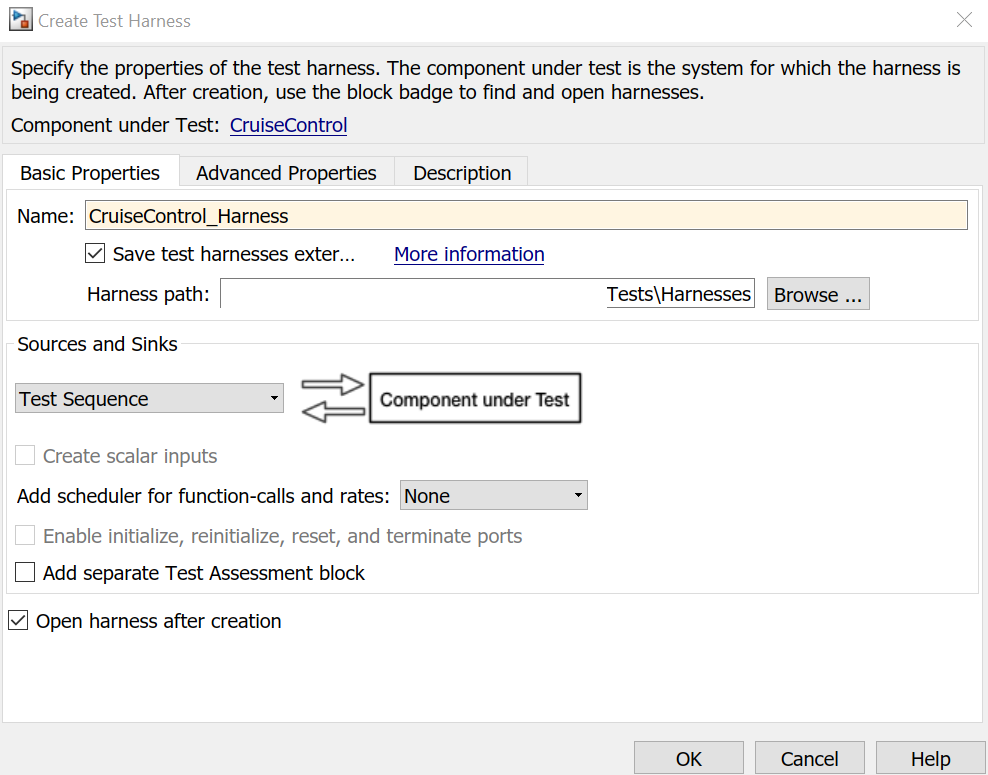

10) Click OK.

## Step 3: Author a Test Using a Test Sequence

A Test Sequence is a type of test input block available with Simulink® Test™. It allows you to write tests that follow a given set of steps that do not have to be time-based. For example, you can transition between test steps based on the value of an input signal. Both the test inputs and the pass/fail criteria can be defined in a Test Sequence block. One advantage of a Test Sequence over time-series based test vectors is that Test Sequences can be easier to maintain and understand since they are based on response to simulation. For more information on Test Sequences, please refer to the [Test Sequence Editor documentation](https://www.mathworks.com/help/sltest/ug/test-sequence-editor.html).

For this example, we will only be defining the test inputs, as we will be using a Temporal Assessment to define the pass/fail criteria.

For reference, here is the requirement you will be testing:

**"The cruise control system shall transition to disengaged from engaged within 0.25 seconds after a braking event has occurred."**

A simple test is to create a braking event while holding all other inputs constant.

Let's write this as a simple test sequence.

Here are the steps to take:

1) Open the Test Sequence Editor by double-clicking on the Test Sequence block in **CruiseControl_Harness.slx**

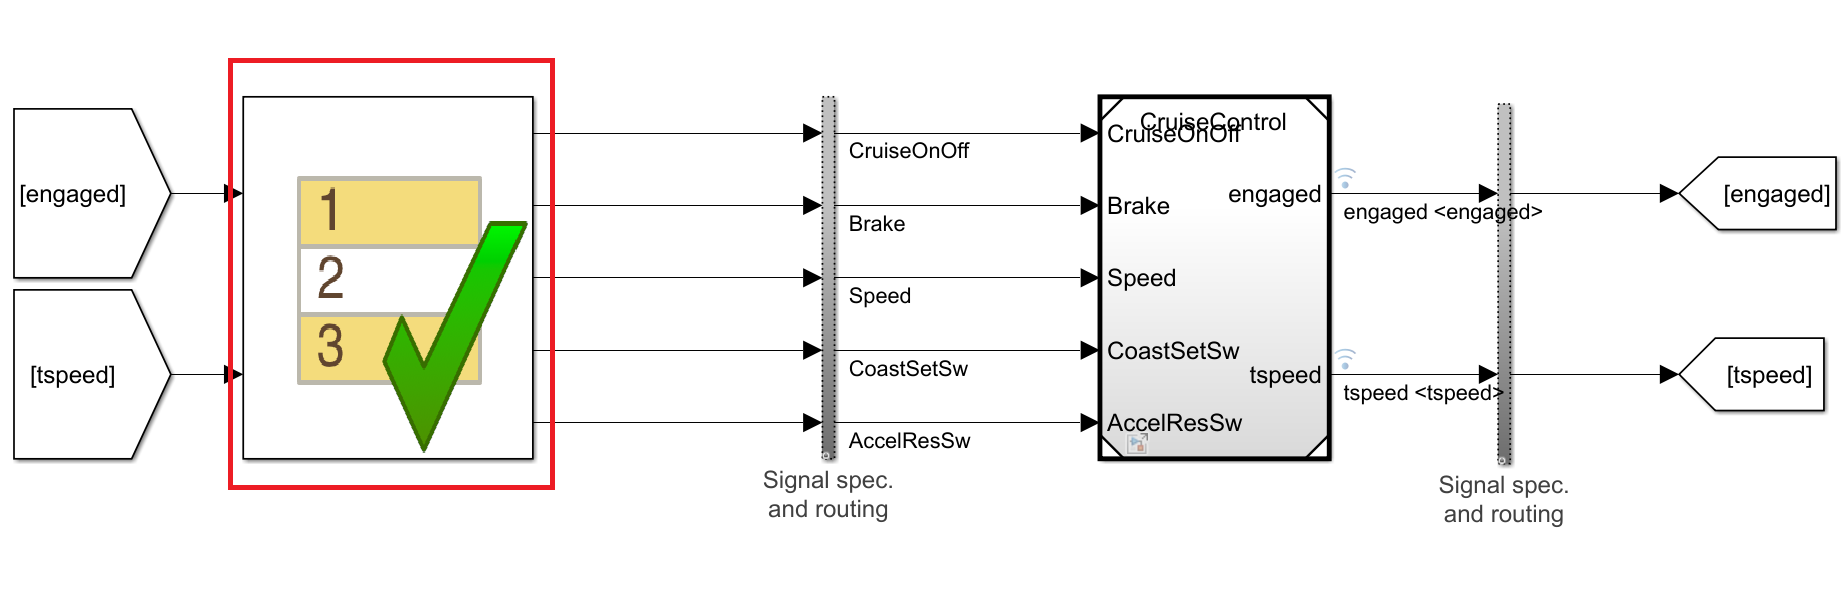

The first step in the Test Sequence is automatically created. It initializes the variables to zero.

2) Let's rename the first step to "Initialize" and change the values for **CruiseOnOff** and **Speed **so that we initialize the test with the vehicle moving and Cruise Control enabled.

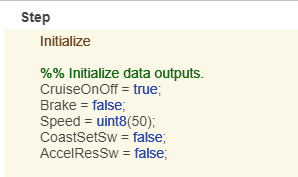

3) Add a new step to the Test Sequence by hovering over the bottom of the first step and clicking "Add step after"

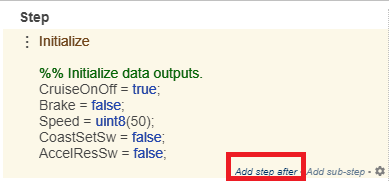

The new step will be called **step_1.**

4) Add a transition from the Initialize step by hovering over the bottom of the Transition cell and clicking "Add transition".

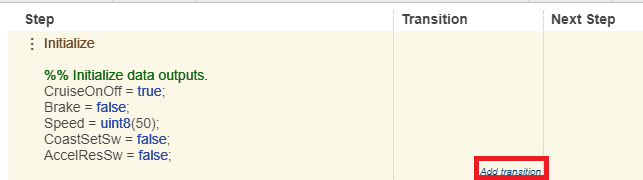

5) We will want to transition to step_1 after 2 seconds. This can be achieved using the "after" function, which should be familiar for Stateflow users.

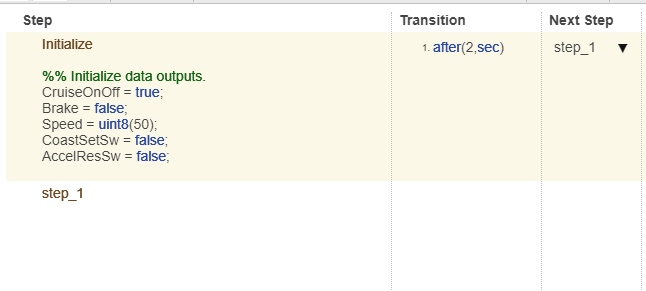

6) In step_1, set the Coast/Set Switch (CoastSetSw) to true. This will engage the cruise control.

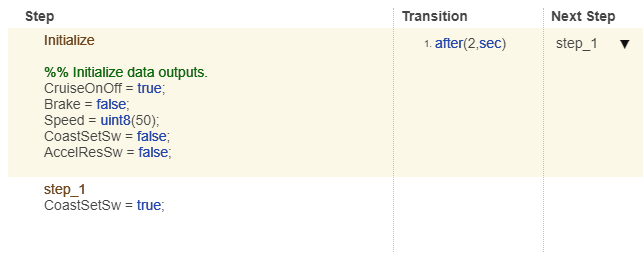

7) Add one more step (step_2). Transition to step_2 after 2 seconds.

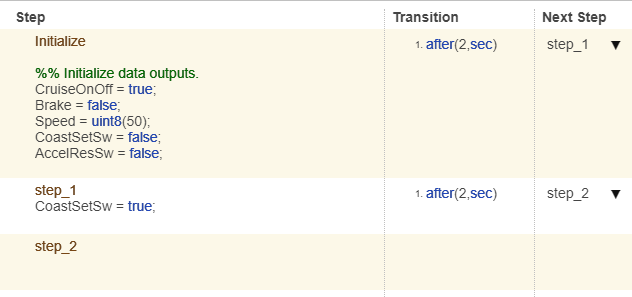

8) In step_2, set Brake to true.

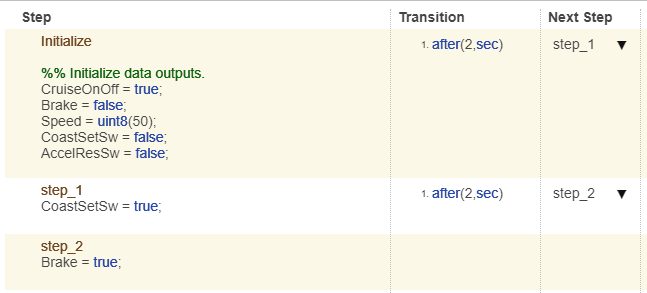

9) Save the Test Sequence

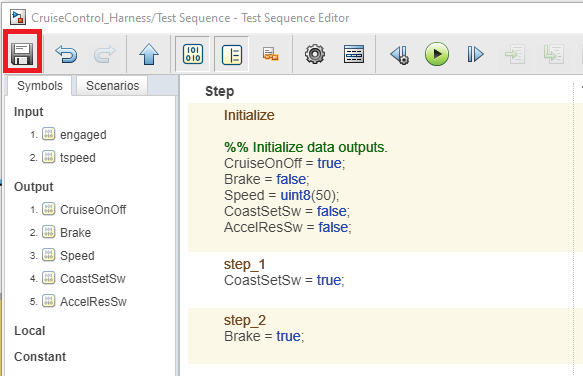

10) Log the **brake** signal. This can be done by right clicking on the signal and selecting "Log Selected Signals".

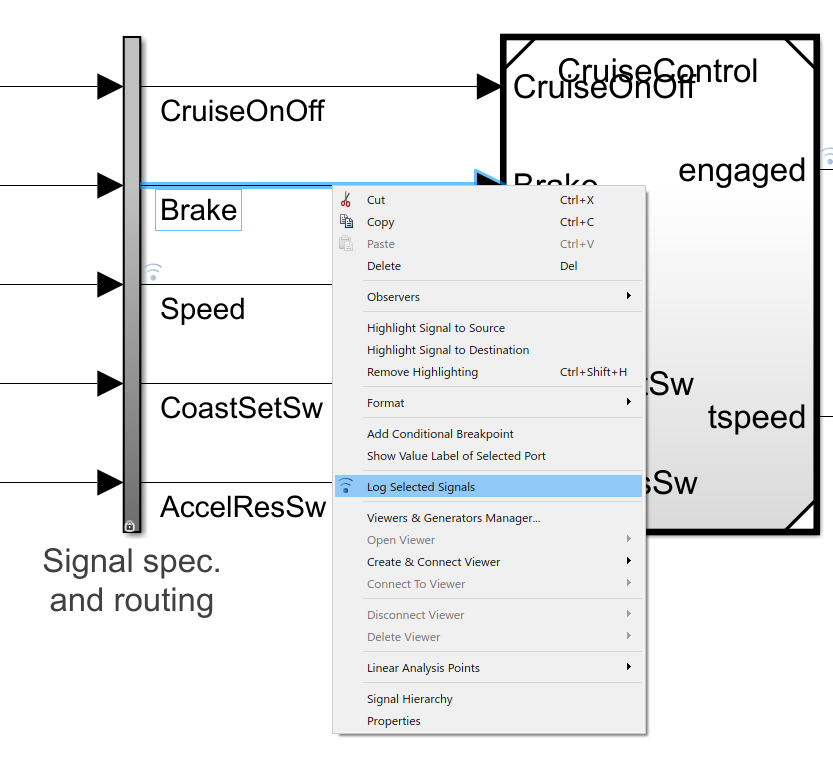

11) Simulate the test harness. Use the Simulation Data Inspector to verify that the engage state is entered and exited (make sure you log the engage signal).

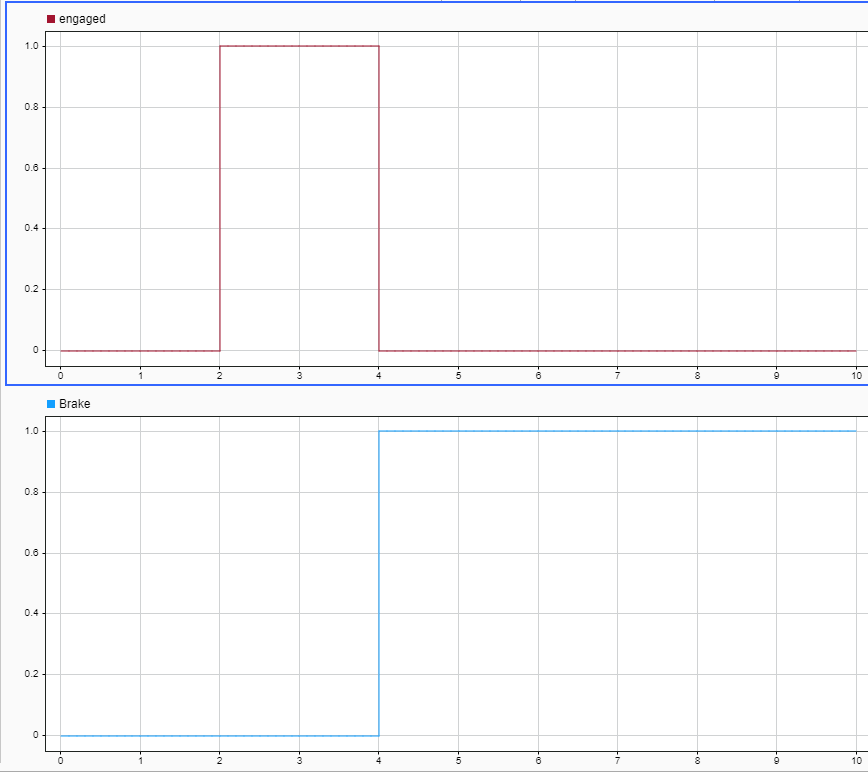

Congrats! You have created a test using a Test Sequence block. 

12) Save and close the harness model.

#### **Bonus: Transition to Next Step in a Test Sequence Based on a Signal's Value**

In addition to time-based step transitions using the after() function, you can also transition to the next step based on the value of a signal.

Here are the first five steps test sequence to test the requirement **"The cruise control system target speed shall be limited between 20 and 90 mph for safe operation"**: 

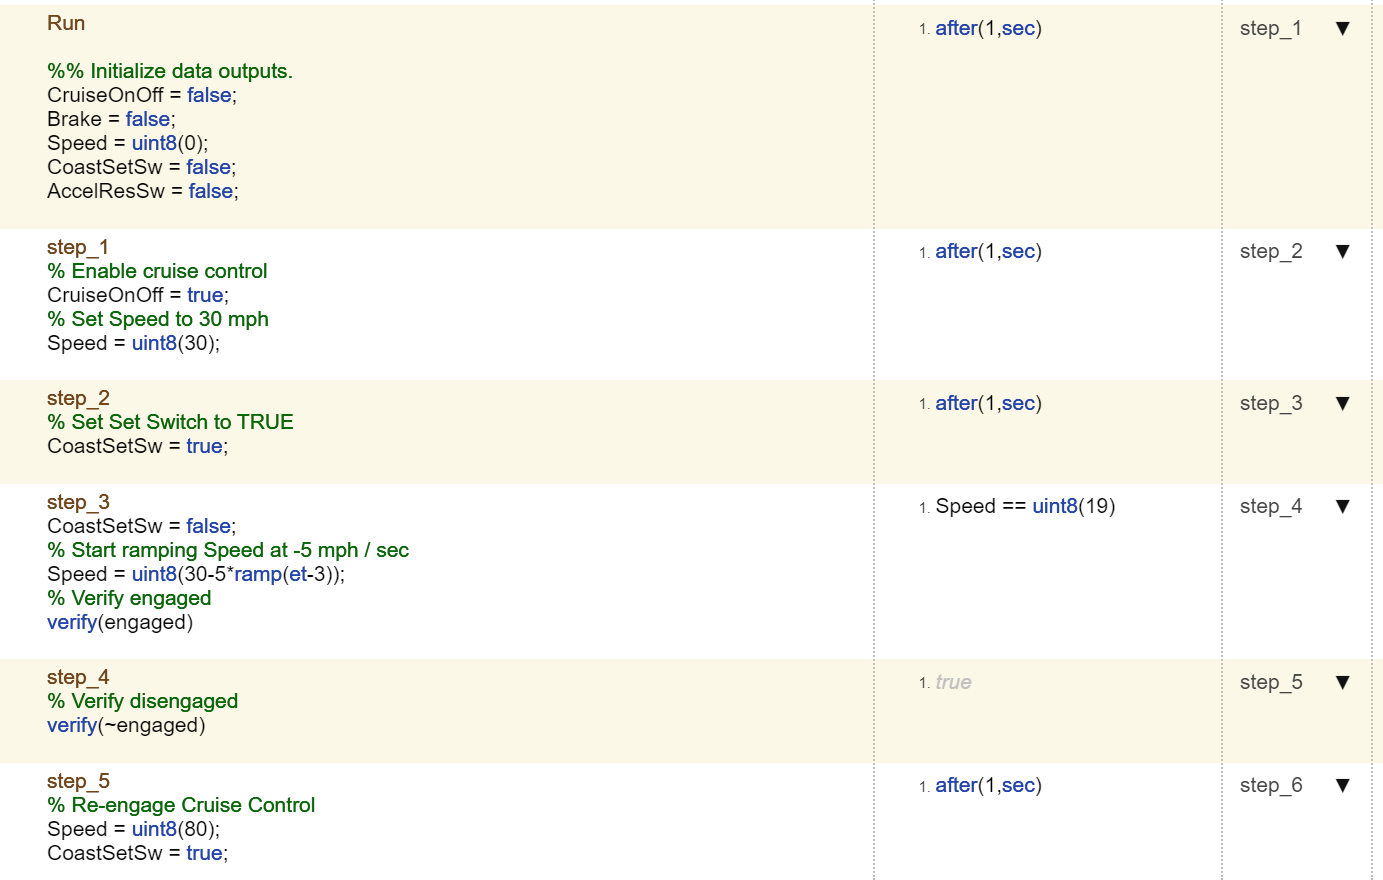

The transition between step_3 and step_4 is based on the value of the Speed signal, which has a value defined using the [ramp function](https://www.mathworks.com/help/sltest/ref/ramp.html). For more information, check out [the documentation](https://www.mathworks.com/help/sltest/ug/act-or-transition-using-temporal-and-event-operators.html).

You can also create scenarios in Test Sequence blocks. For more information, check out [the documentation](https://www.mathworks.com/help/sltest/ug/define-test-sequence-scenarios-in-test-sequence-editor.html).

## Step 4: Create a Test Case Using the Test Manager in Simulink® Test™

Simulink® Test™ includes the Test Manager, which you can use to create and manage test cases.

A test case is a part of a test suite, which is a part of a test file. 

In this example, we will follow the "Verify Model Behavior Against Requirements" workflow documented in the [Create and Run a Baseline Test documentation article.](https://www.mathworks.com/help/sltest/gs/set-up-and-run-tests.html)

To do this, we will create a Simulation Test, which will verify whether the model has correctly implemented the requirements.

Another common test case type is a  Baseline Test, which compares the outputs from a simulation against expected outputs, which are often captured from an earlier simulation. You can learn more about creating a Baseline Test in the "Create and Run a Baseline Test" in [the same article](https://www.mathworks.com/help/sltest/gs/set-up-and-run-tests.html).

Here are the steps to take:

1) Open the Test Manager

You can open the Test Manager via the Simulink® Test™ app toolstrip by clicking on the "Simulink® Test™ Manager" button. Let's do this from the **CruiseControl.slx** model

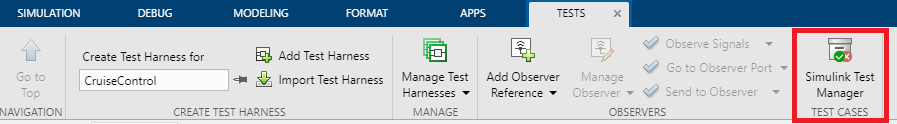

You can also open the Test Manager by running the following command:

sltestmgr

2) Create a new test file from the **CruiseControl.slx** model.

In the Test Manager, click **New -> Test File from Model**

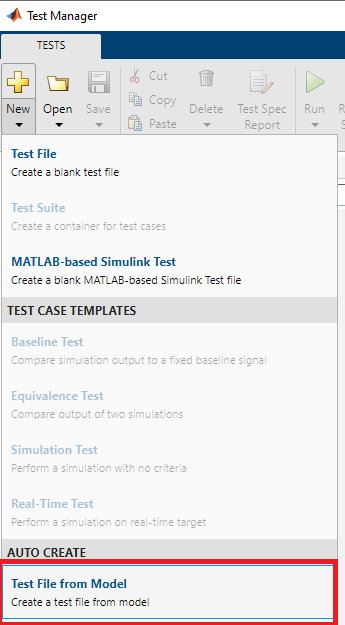

3) In the New Test File window, next to the Model text box, click on the icon to the ride labeled "Use current model".

In the Location field, name the test file **CruiseControlTest.mldatx. **Save it to the **Tests** folder.

Set the Test Type to Simulation.

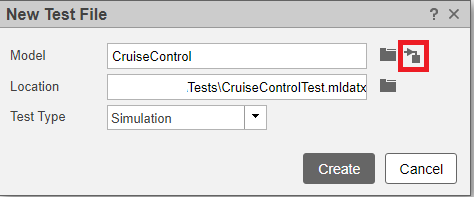

4) Click **Create**

 The test case "CruiseControl_Harness"  will be created using the **CruiseControl_Harness.slx** model created earlier.

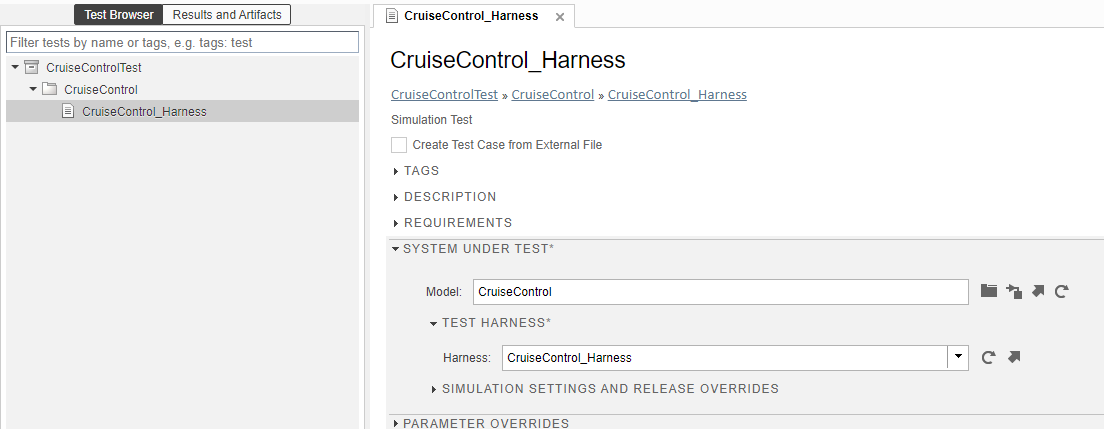

## Step 5: Create a Temporal Assessment for Pass/Fail Criteria

Next, we want to create pass/fail criteria for the test.

Let's use a Temporal Assessment to do this. A Temporal Assessment allows you to test timing-dependent logic using expressions that are readable and mathematically consistent. Since the requirement we want to test involves timing, we will use a temporal assement to define our pass/fail criteria.

Here are the steps to take:

1) Click on the **CruiseControl_Harness** test case (be sure the Test Browser tab is active)

2) Click on the drop-down to the **LOGICAL AND TEMPORAL ASSESSMENTS** menu.

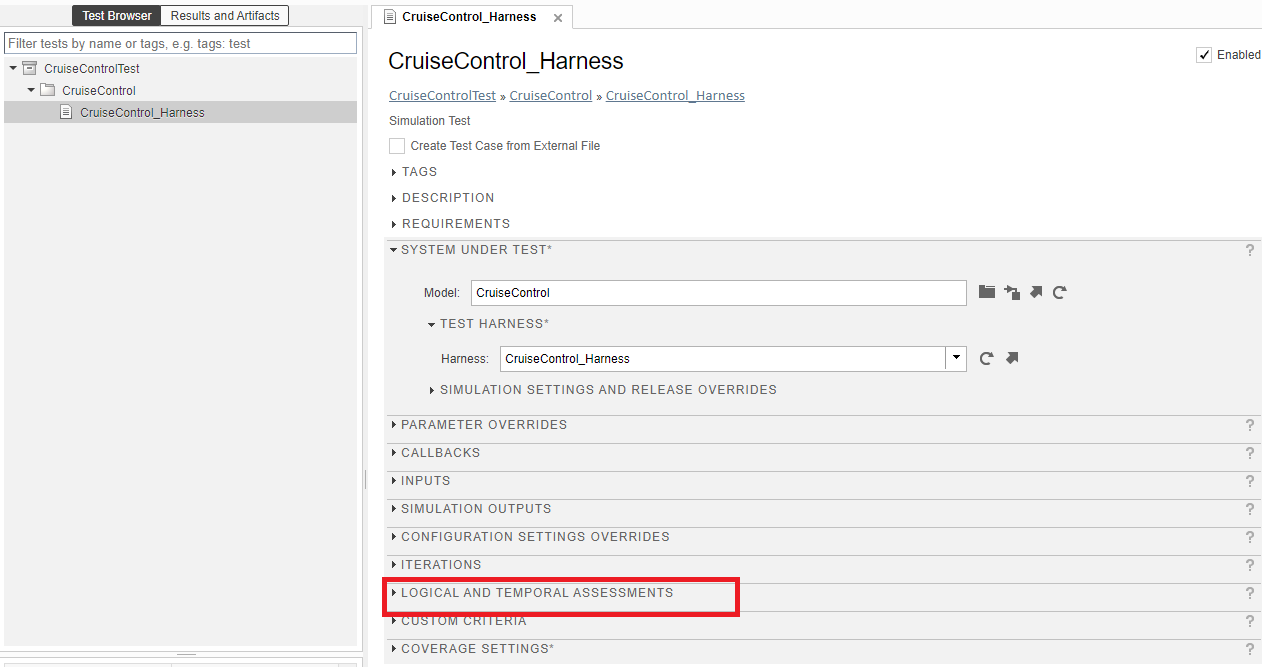

3) Click **Add Assessment**

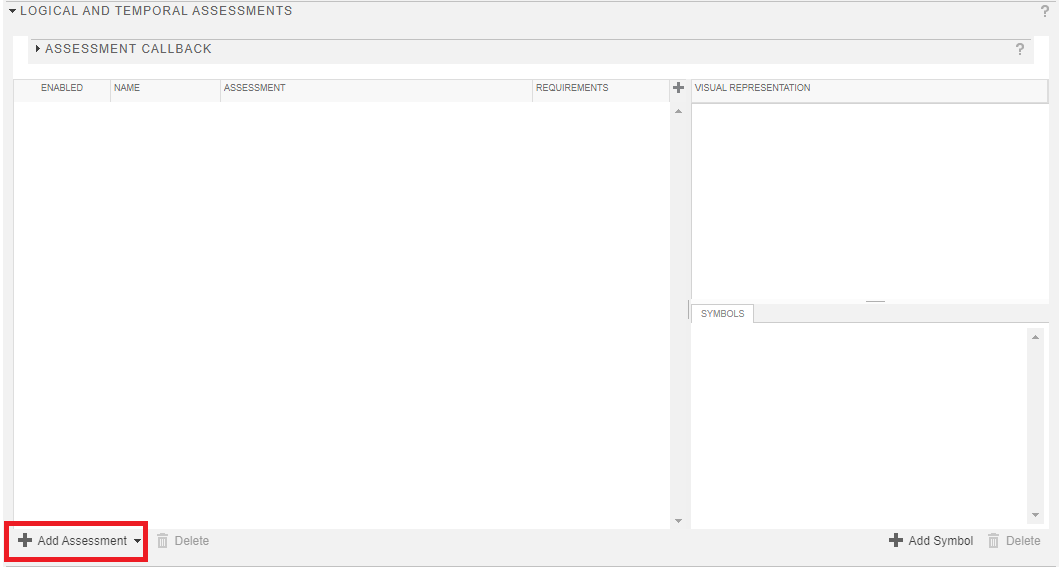

4) Select **Trigger-response**

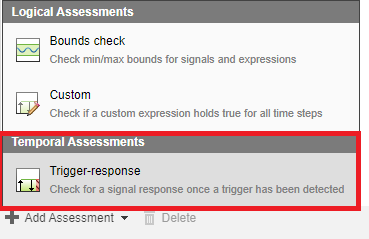

You can now define the expected behavior, which is for the **engaged **signal to go from TRUE to FALSE within 0.25 seconds of the **brake **signal becoming TRUE.

To do this:

1) Select the drop-down for "trigger" -> "becomes true"

2) Set condition: **brake**

We will "map" the "brake" symbol later. Just type in "brake" for now.

3) Select the drop-down for "delay" -> "with a delay of at most"

4) Set max-time (sec): 0.25

5) Select the drop-down for "response" -> "must be true"

6) Set condition: **~engaged**

Let's name the assessment "Disengage after brake".

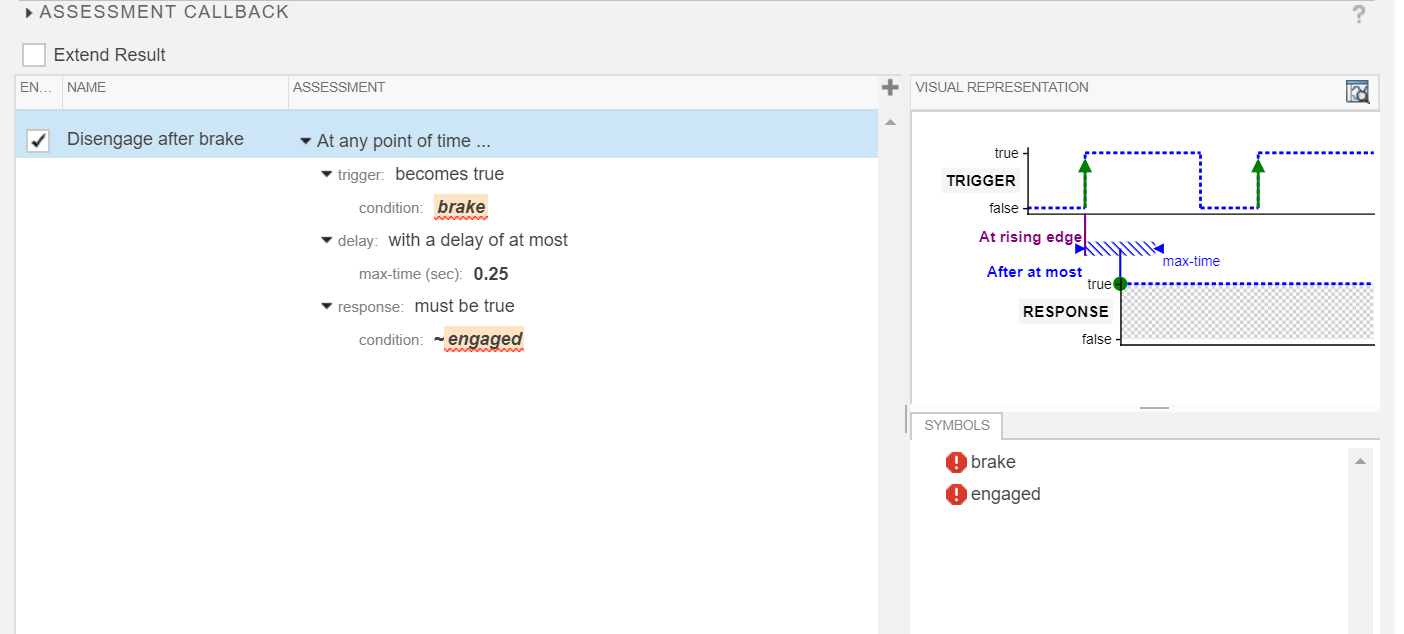

You will see two unresolved Symbols in the "SYMBOLS" pane to the right: "**brake**" and "**engaged**".

You then need to map the **brake **and **engaged **signals to the test harness model.

To do this:

1) Select the icon to the right of the **brake **symbol in the SYMBOLS section -> "map to model element"

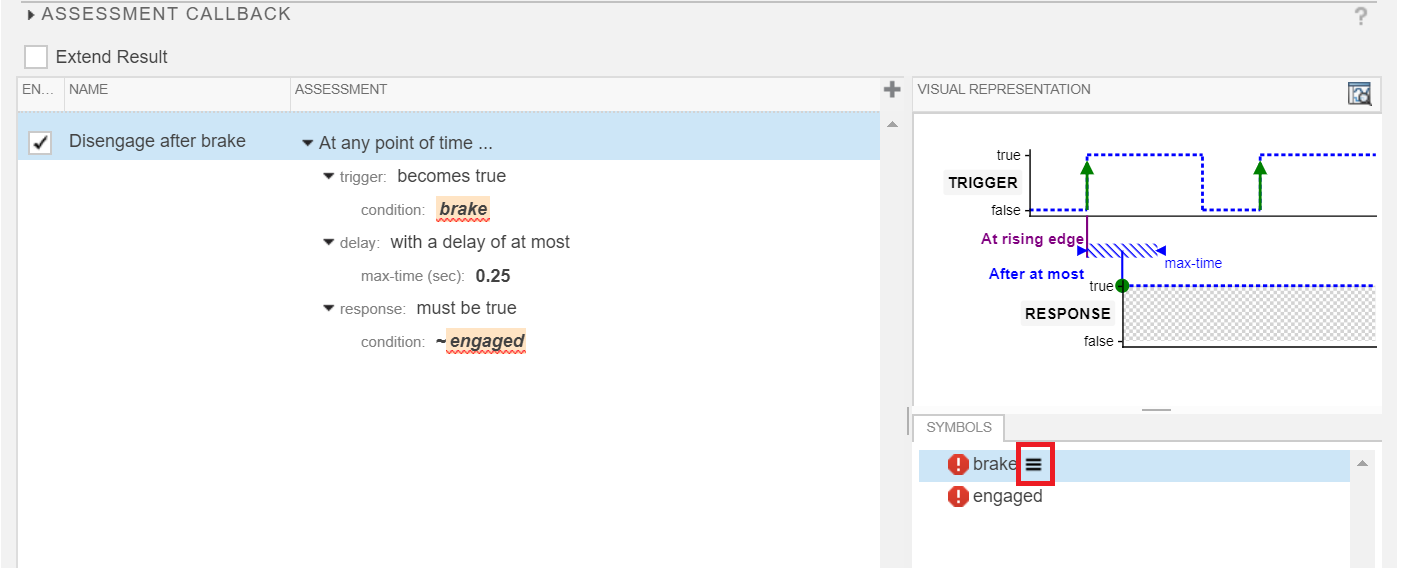

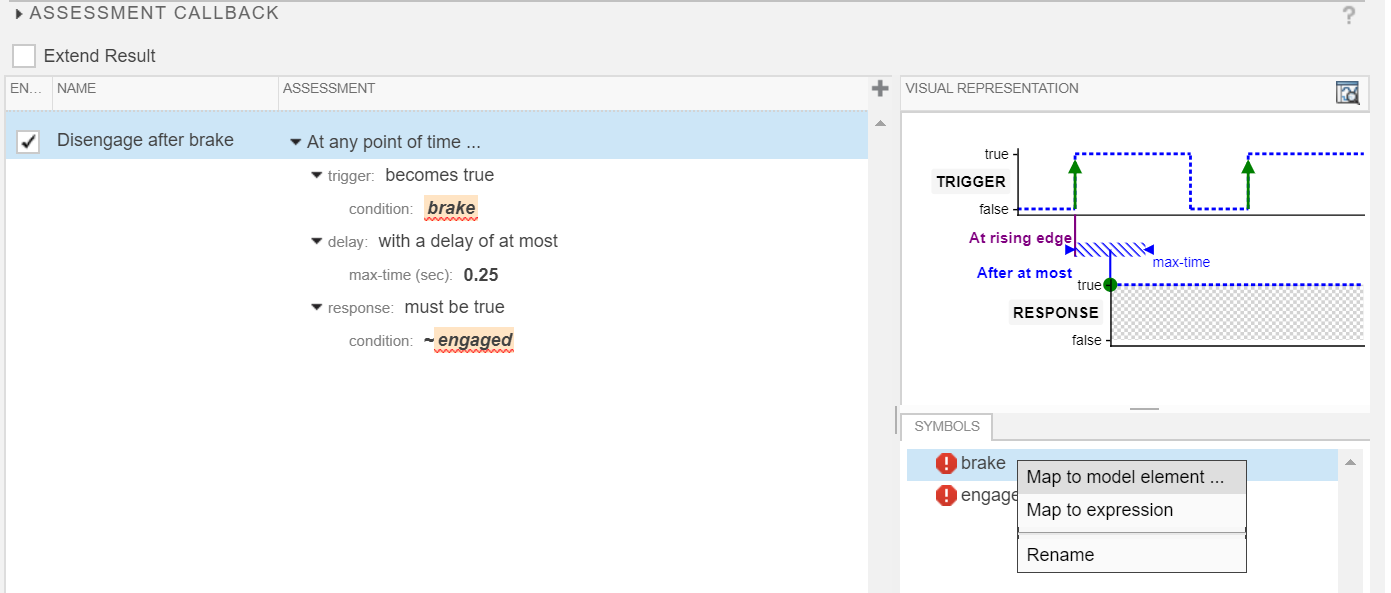

2) Within the model, select the signal line for **brake**. You should then see the "Connect" pop-up appear. 

Click the radio button for "Brake"

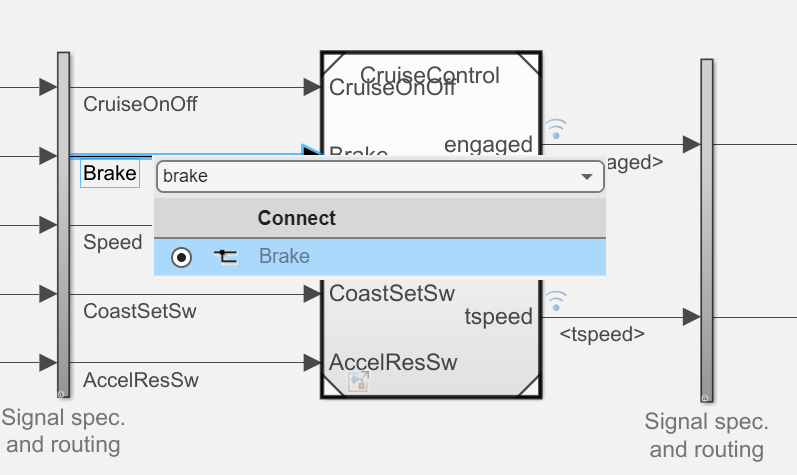

3) Click on the line for the **engaged **signal output from the model

4) Click on the drop-down to select **engaged**. This will map the selected signal to the engaged symbol in the Test Manager.

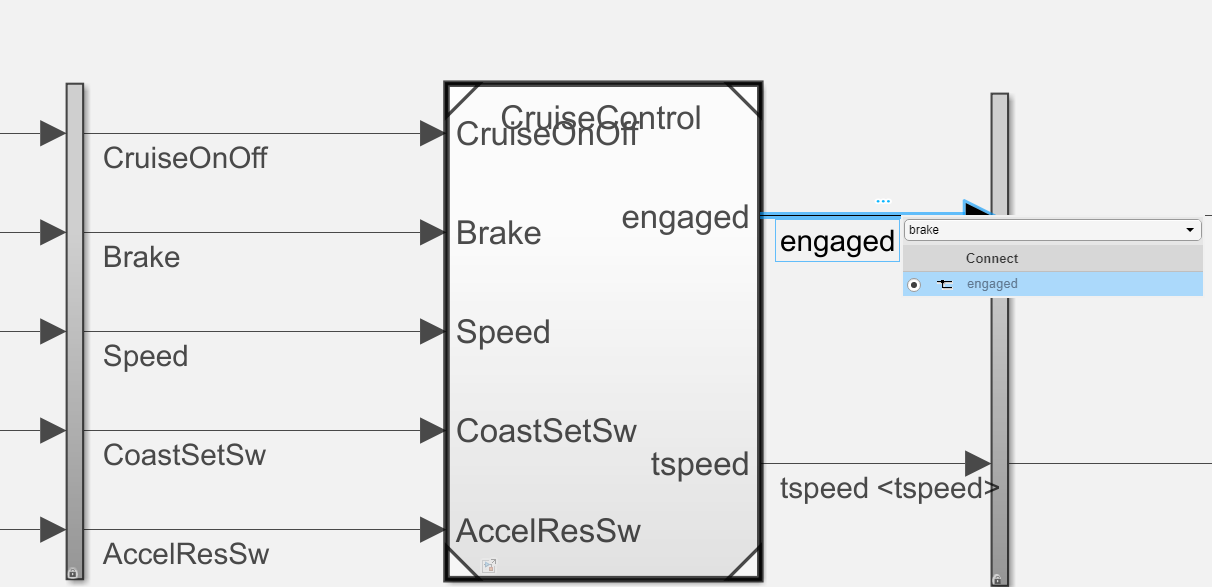

5) Back in the Test Manager window, click **DONE**

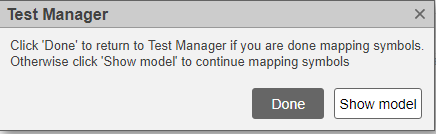

When you are done, the Temporal Assessment should look like this:

 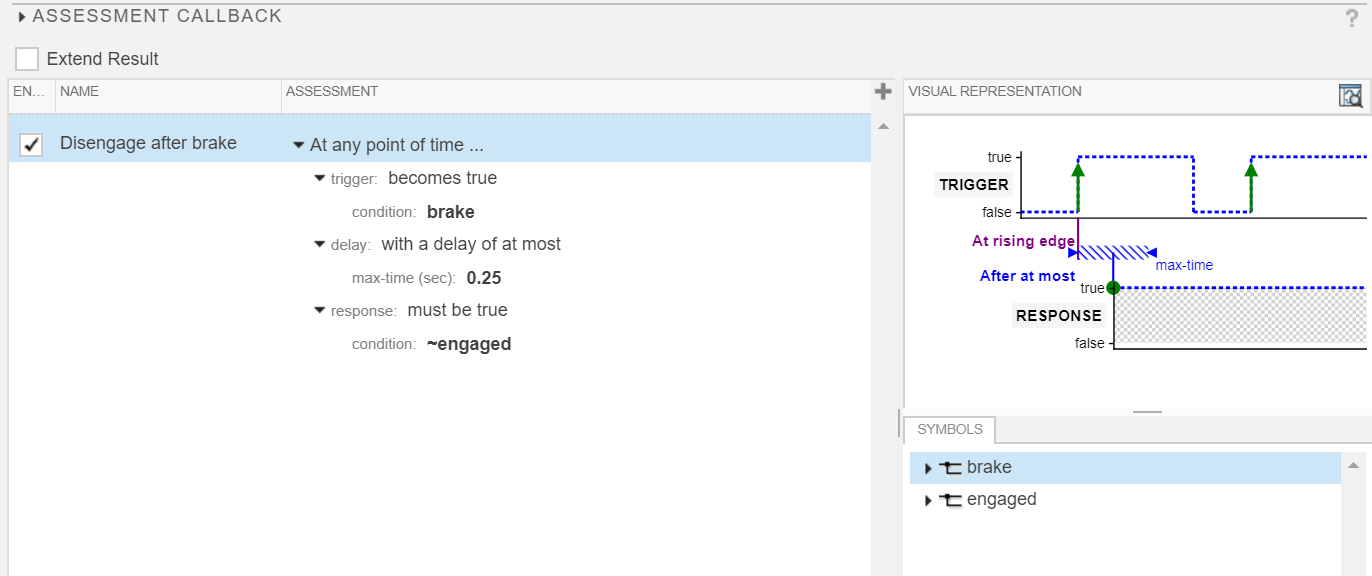

You can collapse the assessment into a more readable form:

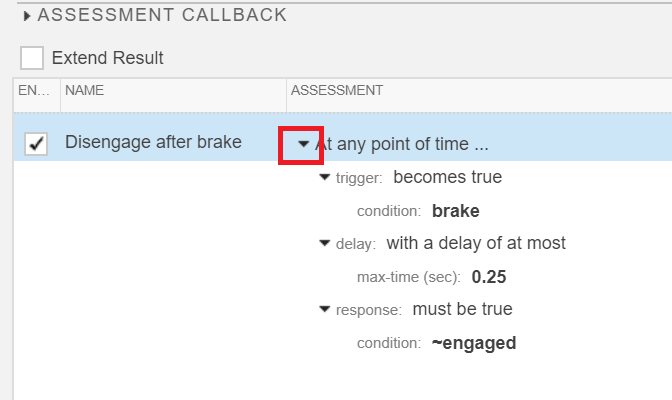

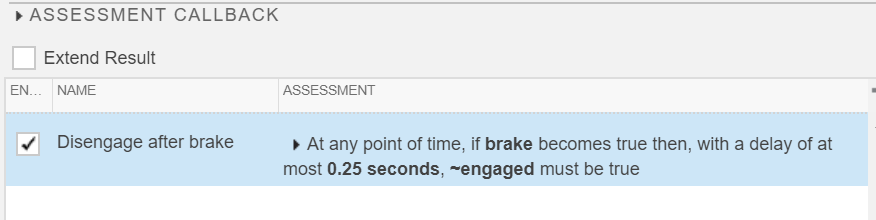

#### Bonus: Temporal Assessment API

You can use the Temporal Assessment API to programmatically copy and modify Temporal Assessments. For more information, check out [the documentation](https://www.mathworks.com/help/sltest/ref/sltest.testmanager.assessment-class.html).

## Step 6: Execute the Test Case

Now that we have established our test inputs and pass/fail criteria, it's time to execute the test case to see if it passes.

To execute the test case, select it in the Test Manager and click the **Run** button in the toolstrip. You can also use the keyboard shortcut **CTRL + T** after selecting the test case.

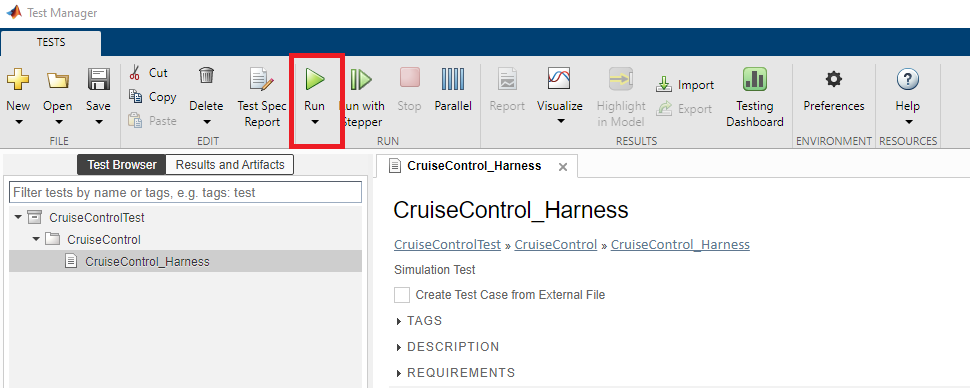

The Test Manager will automatically switch from the Test Browser tab to the Results and Artifacts tab, where you can see the progress of the test case execution.

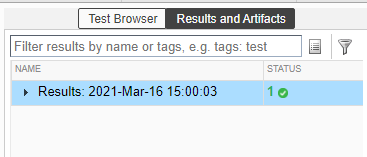

Congratulations! The test case passed.

**OPTIONAL**: Try modifying the Temporal Assessment criteria to make the test fail.

## Step 7: Link the Test Case to the Requirement

Now that we have a working test case, let's make sure we link the test case to a requirement. This can all be done within Simulink® using Simulink® Test™ and Requirements Toolbox™.

By linking a test case to its associated requirement, we can later execute the test case directly from Requirements Toolbox™.

We will be using a Traceability Matrix to create a link. A Traceability Matrix allows you to create and view requirements and links to several items.

Here are the steps to take:

1) If you have closed them, re-open the **CruiseControl** requirements set and **CruiseControlTest** test file using the following code:

slreq.open('CruiseControl');
sltest.testmanager.load('CruiseControlTest.mldatx');
sltest.testmanager.view

2) In the Requirements Editor, click on the Traceability Matrix button in the Toolstrip:

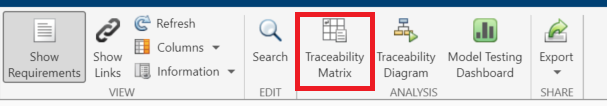

This will open the Traceability Matrix window.

3) In the Traceability Matrix window, click the "Add" button:

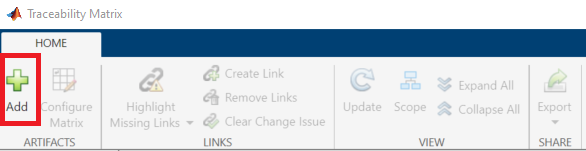

This will launch the Select Artifacts window, which you can use to generate a traceability matrix between two artifacts (e.g., a requirements set and a test suite).

4) In the Select Artifacts window, select **CruiseControl.slreqx** for the Left artifact and **CruiseControlTest.mldatx** for the Top:

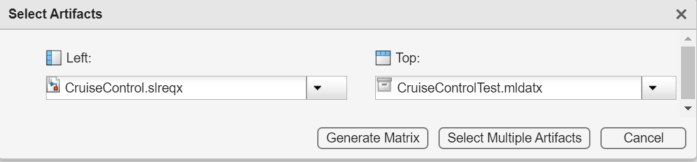

5) Select Generate Matrix

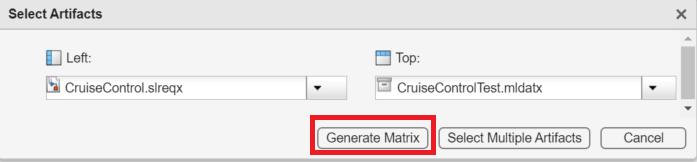

6) In the generated Traceability Matrix, navigate to the Safety requirements section to the row for "Disengage when braking occurs requirement."

We want to link this requirement to the CruiseControl_Harness test case.

To do this, click on the corresponding cell in the matrix, then click "Create"

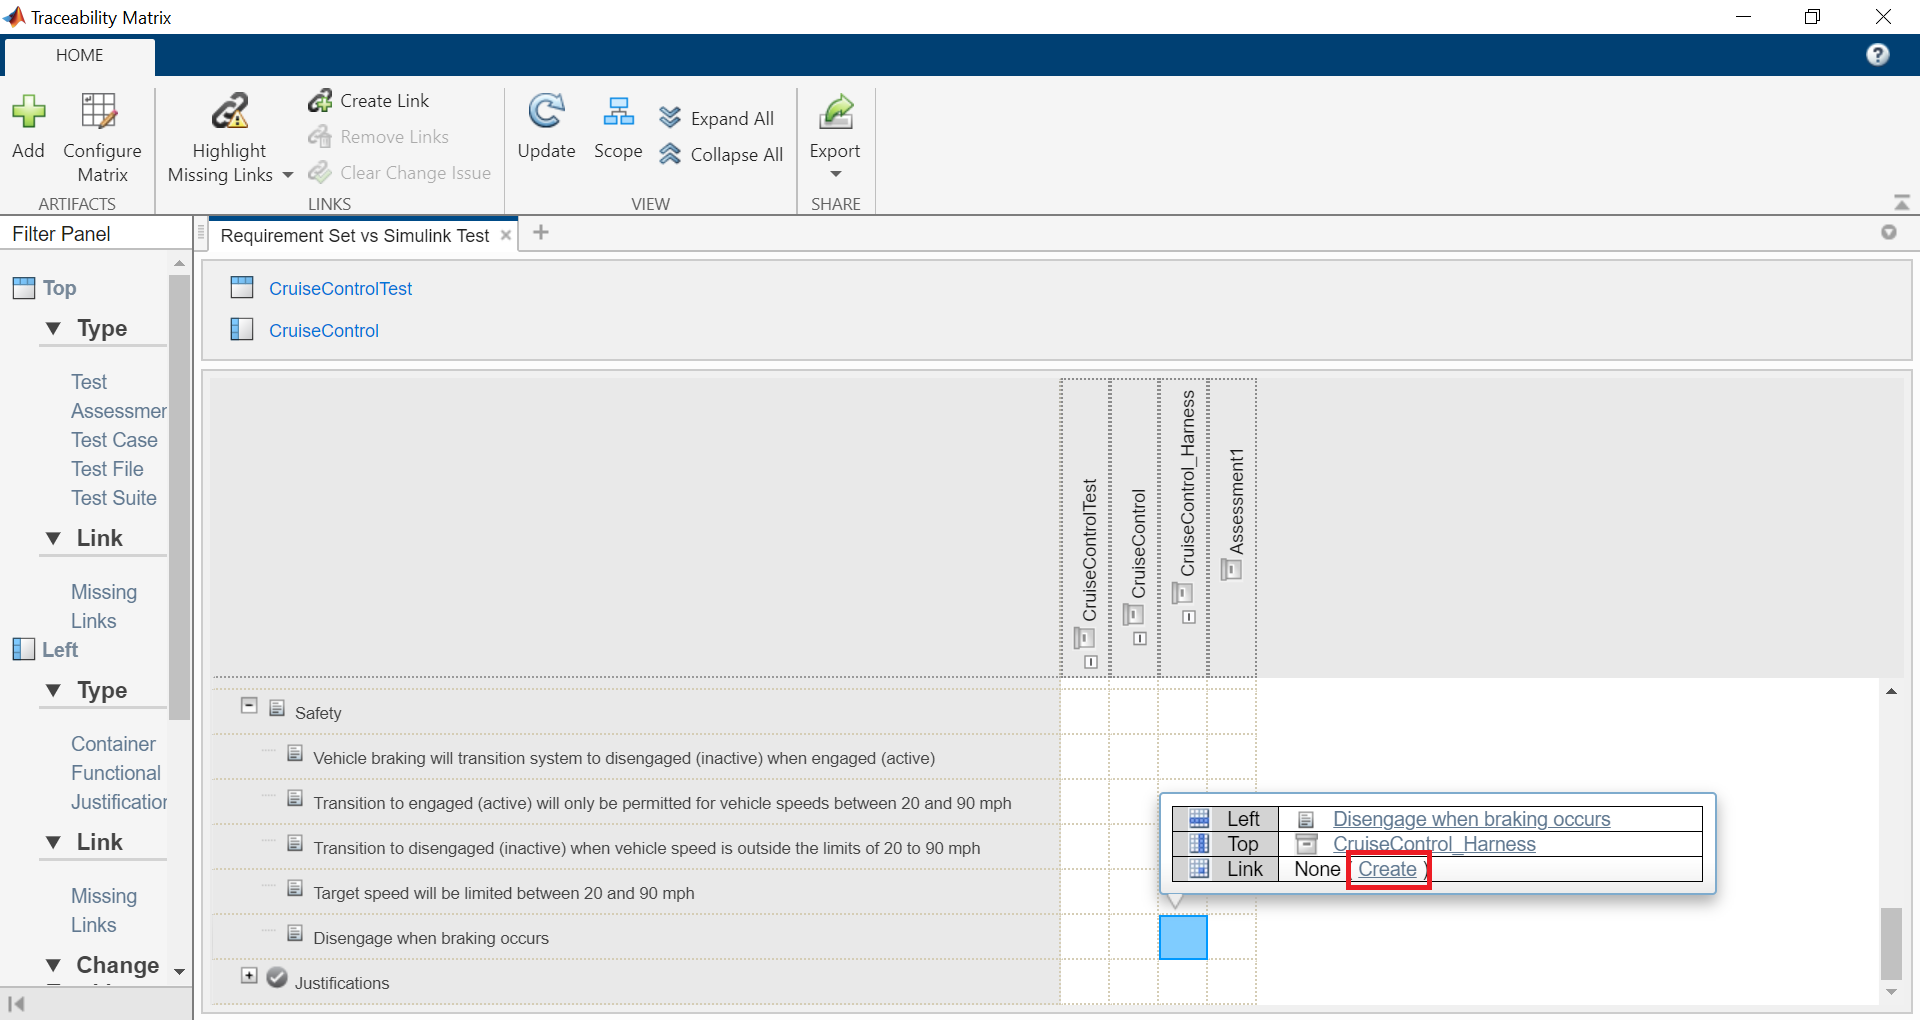

You can create additional links between artifacts within the same Traceability Matrix.

Congrats! You have successfully created a new test case using a Test Sequence and a Temporal Assessment, as well as linked the test case to its relevant requirement.

Be sure to take the following steps before moving on to Part 2:

- Close all open models

- Close the Requirements Editor window

- Close the CruiseControl_Test Test File in the Test Manager window

- Close the Traceability Matrix window

You will not be using any of the files from Part 1 in Part 2 of this example.

# **Part 2: Run a Test Suite and Resolve Missing Model Test Coverage**

In Part 2 of the example, we will be running a full suite of tests to make sure we have fully tested the design.

The goals for this part are to learn how to:

- execute a test suite using Simulink® Test™

- measure test coverage

- generate tests to analyze missing test coverage

- resolve missing test coverage

Model test coverage, or "model coverage," is a measure of how much of your design has been tested through simulation. Having full model coverage ensures that you have accounted for all behavior in your model. Missing model coverage may be the result of dead logic, incomplete testing, unexpected functionality, or incomplete/missing requirements.

In addition to Requirements Toolbox™ and Simulink® Test™, which you used in Part 1, you will be using the following products in Part 2:

**Simulink® Coverage™ **is used to measure test coverage for Simulink models and generated code.

**Simulink® Design Verifier™** is used to detect design errors, generate tests to achieve test coverage goals, and formally verify requirements using static analysis.

You will be running a pre-created test suite within Simulink® Test™. This test suite contains several test cases, each of which has been linked to its relevant requirements.

A best practice is to limit the scope of a test to its related requirements. This is done in order to make it easier to analyze why a test failed. A test that addresses many requirements may seem more efficient, but can become burdensome to troubleshoot when the test fails. In addition, as the requirements and design mature, regression testing can be made easier by having more narrowly scoped tests. In short: try to maintain a 1:1 relationship between requirements and tests whenever possible. With this in mind, most of the tests in the pre-created test suite were written to test a single requirement.

In addition, you will be using a suite of Baseline Tests in Part 2 of the example. In Part 1, you created a Simulation Test in order to verify the implementation. A Baseline Test can also be used for this purpose, but also includes the ability to capture a baseline to compare results in subsequent simulations to determine if there is a regression. However, baselines are generally only useful once you have tests which already pass based on requirements.

Before a baseline is captured, let's make sure:

1) The tests pass based on requirements

2) The model has been completely exercised based on requirements.

At the end of this part, you will go through how to set up a Baseline Test to capture a baseline, which can be used in subsequent simulations as expected criteria.

**Note**: Simulink Test uses a Baseline Test as the default test type. You can convert between test types in the Test Manager for a single test case by right-clicking on the test case and selecting "Convert to".

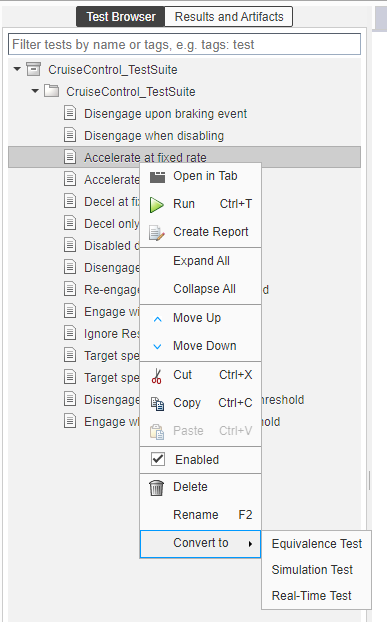

You can also use the [TestSuite](https://www.mathworks.com/help/sltest/ref/sltest.testmanager.testsuite-class.html) and [TestCase](https://www.mathworks.com/help/sltest/ref/sltest.testmanager.testcase-class.html) APIs to convert between different test types for an entire test suite. [**Click here**](matlab:edit('convertToSimulationTests.m')) to see a MATLAB script which shows how to do this.

## Step 1: Open Test Suite in Test Manager

Run the following code to open the test file in the Test Manager:

sltest.testmanager.clear % clears test files from Test Manager
sltest.testmanager.load('CruiseControl_TestSuite.mldatx');
sltest.testmanager.view

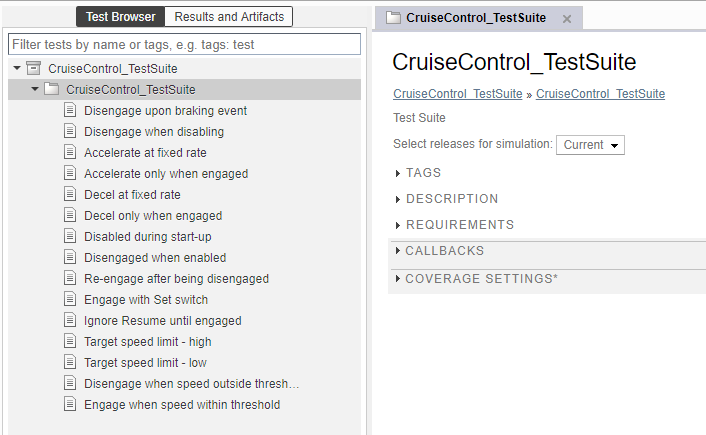

The test suite consists of several test cases, each of which tests a single requirement.

## Step 2: Enable Coverage Collection

We now need to enable model coverage collection for the test suite. This is known as "aggregated coverage", because model coverage is collected for each test case and then aggregated across all test cases in the test suite.

Model coverage is collected by **Simulink® Coverage™**, which is a separate product from Simulink® Test™.

To enable model coverage collection:

1) Click on the **CruiseControl_TestSuite** test suite in the Test Browser in the Test Manager

2) Open the COVERAGE SETTINGS section

3) Select "Record coverage for system under test"

In the COVERAGE METRICS section, the following metrics are already selected: Decision, Condition, and MCDC. [**Click here**](https://www.mathworks.com/help/slcoverage/ug/types-of-model-coverage.html) to learn more about these coverage metrics.

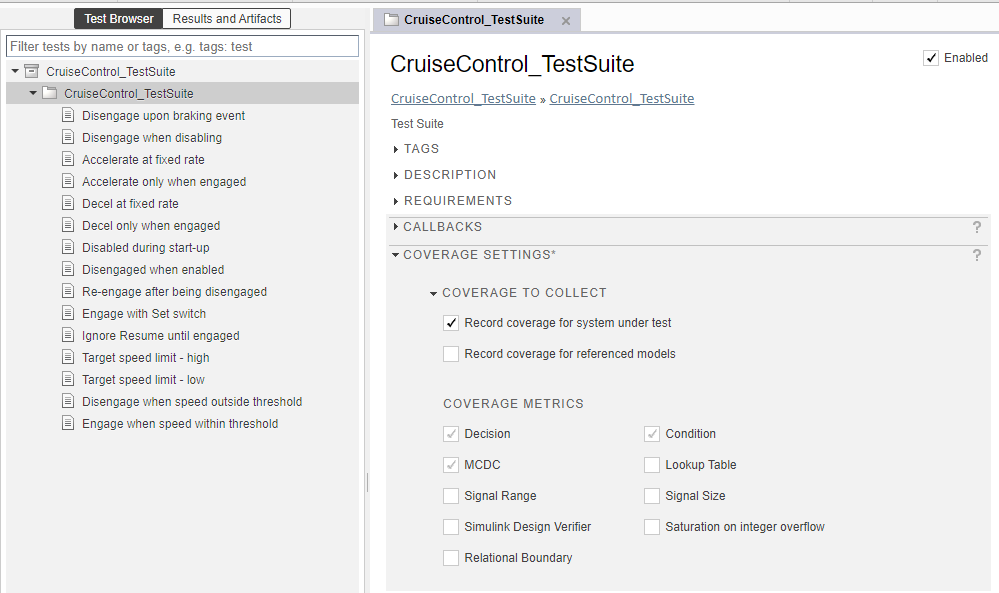

## Step 3: Execute Test Suite

To execute the test suite:

1) Select the test suite **CruiseControl_TestSuite** in the Test Browser 

2) Click **Run** in the toolstrip or by using the keyboard shortcut **CTRL + T**

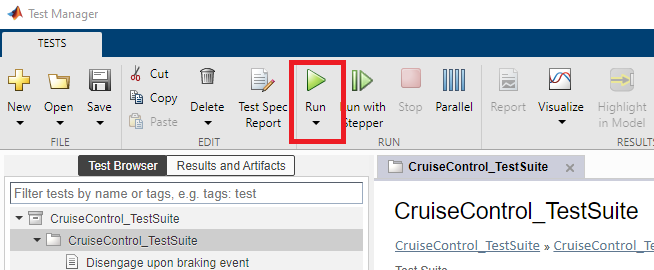

The Test Manager will automatically switch to the **Results and Artifacts** tab to show the test execution progress. This test suite has 15 test cases.

## Step 4: View Model Coverage Results

1) To view model coverage results, click on the most recent test run in the **Results and Artifacts** tab in the Test Manager, then look under AGGREGATED COVERAGE RESULTS.

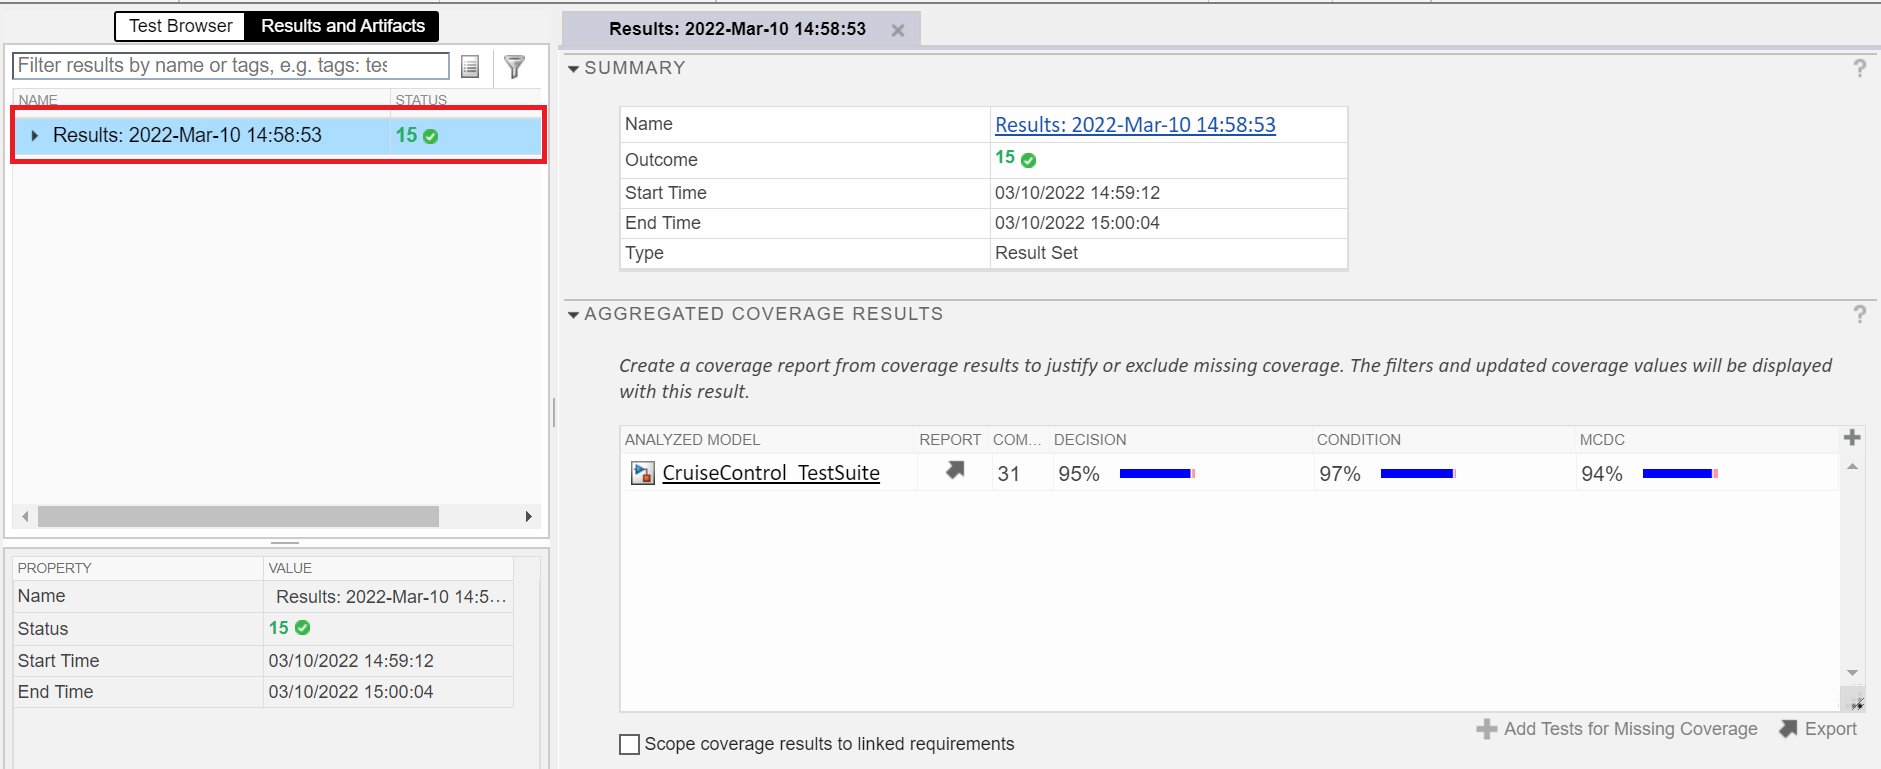

Wow, that's pretty good coverage!

However, before we move on, let's make sure the coverage received is based on the correct requirements, which we'll refer to as "requirements-scoped coverage." For more information on this concept, please refer to the video [How to Scope Model Coverage to Requirements-Based Tests](https://www.mathworks.com/videos/how-to-scope-model-coverage-to-requirements-based-tests-1585910927242.html).

2) Click on the checkbox for "Scope coverage results to linked requirements"

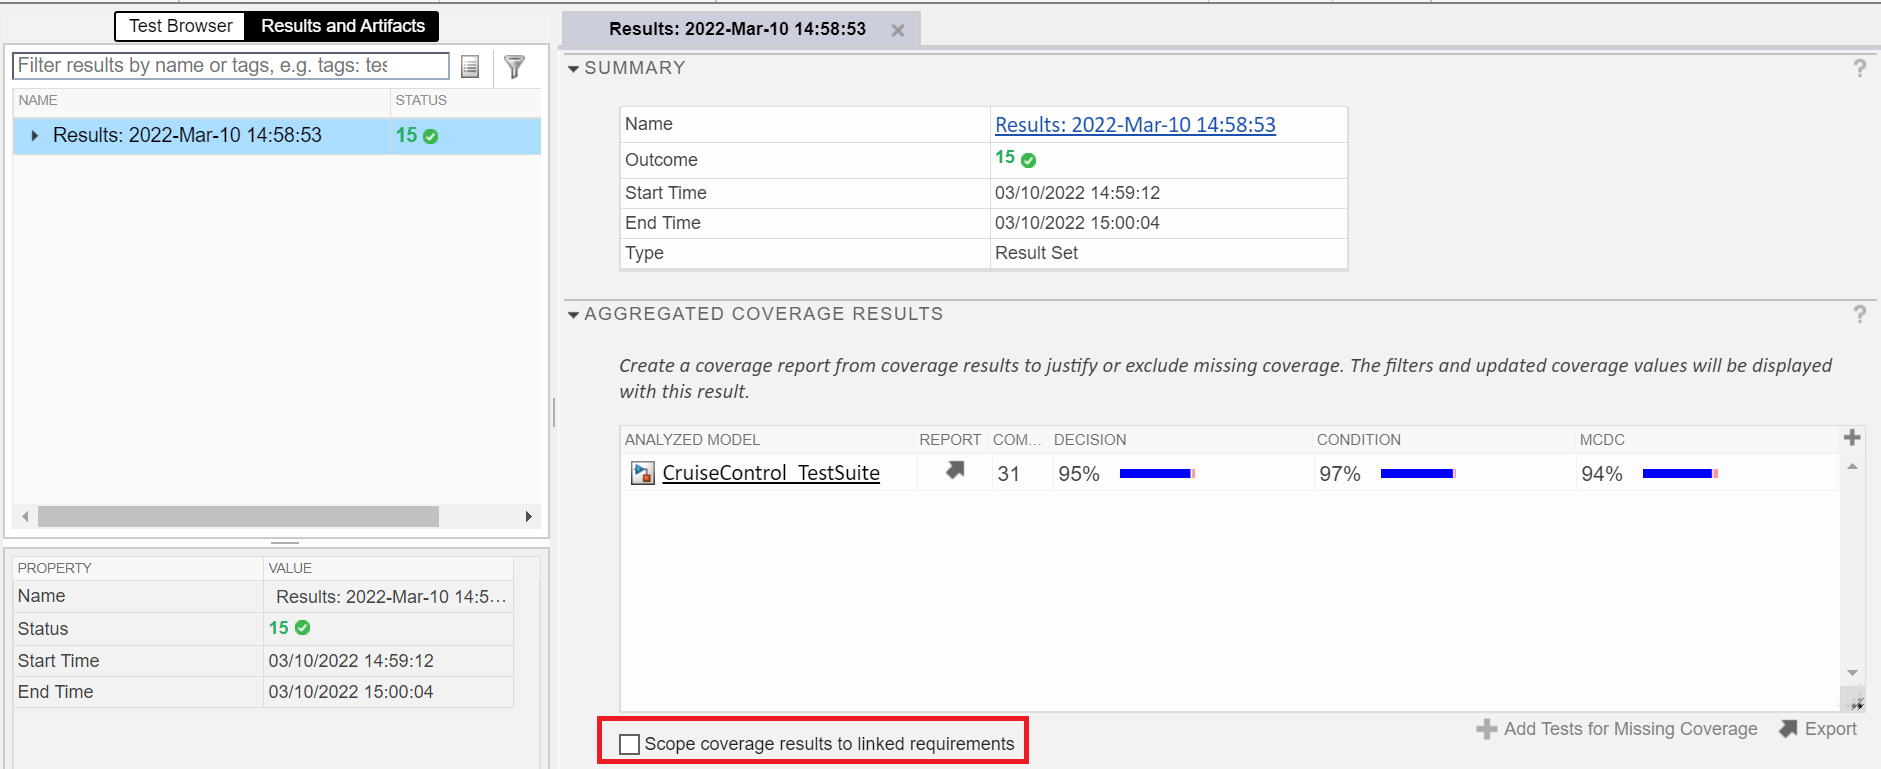

The AGGREGATED COVERAGE RESULTS will then be "scoped" based on requirements:

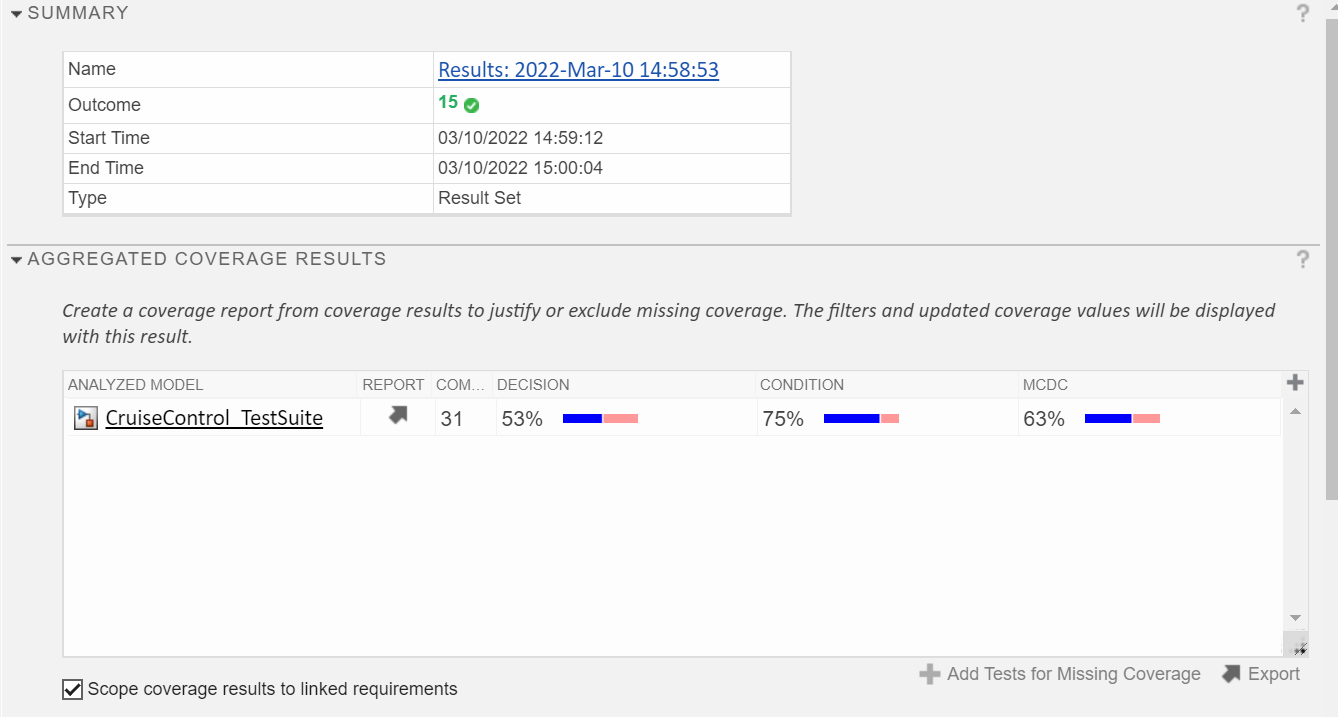

Wow! It looks like we lost a lot of coverage.

This is due to "incidental coverage", which is when a test case exercises a part of the model which is not associated with a common requirement. In "requirements-scoped" coverage, an objective is fully covered if a test case which is associated with that objective's model element exercises the objective.

Let's open the coverage report to investigate further.

3) Click on the report icon in AGGREGATED COVERAGE RESULTS

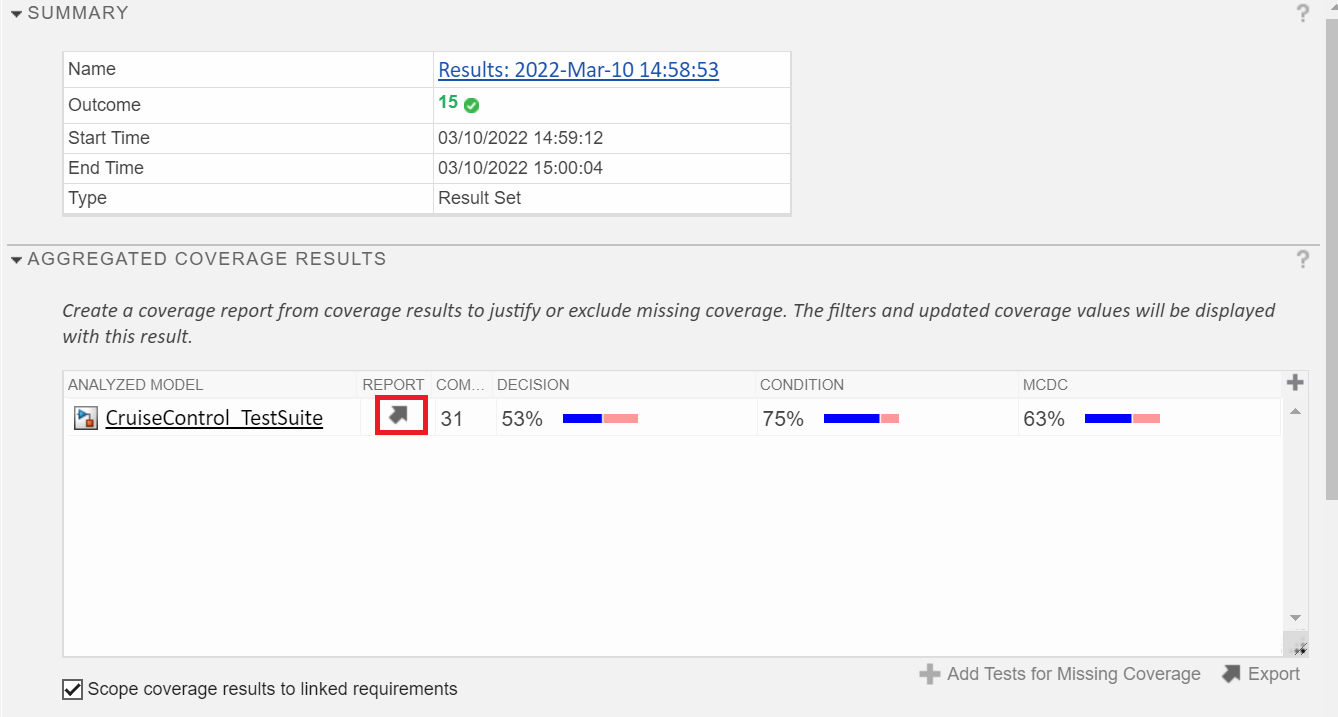

Let's start by looking at the model elements with the lowest coverage.

4) In the Summary section, click on the **SF:ON** state.

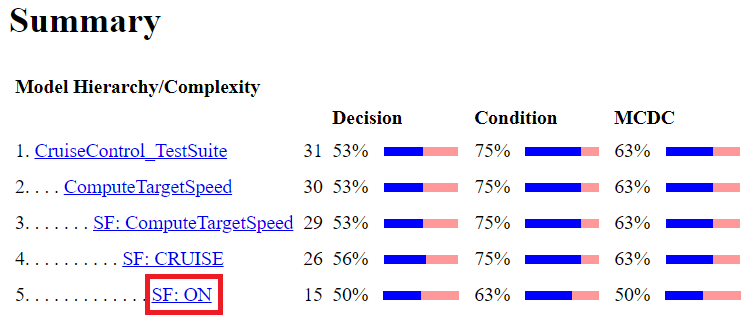

"Incidental coverage" will show up in the coverage report as a coverage objective in red (indicating missing coverage) with a test case listed.

Here is an example demonstrating this with the "ON" state:

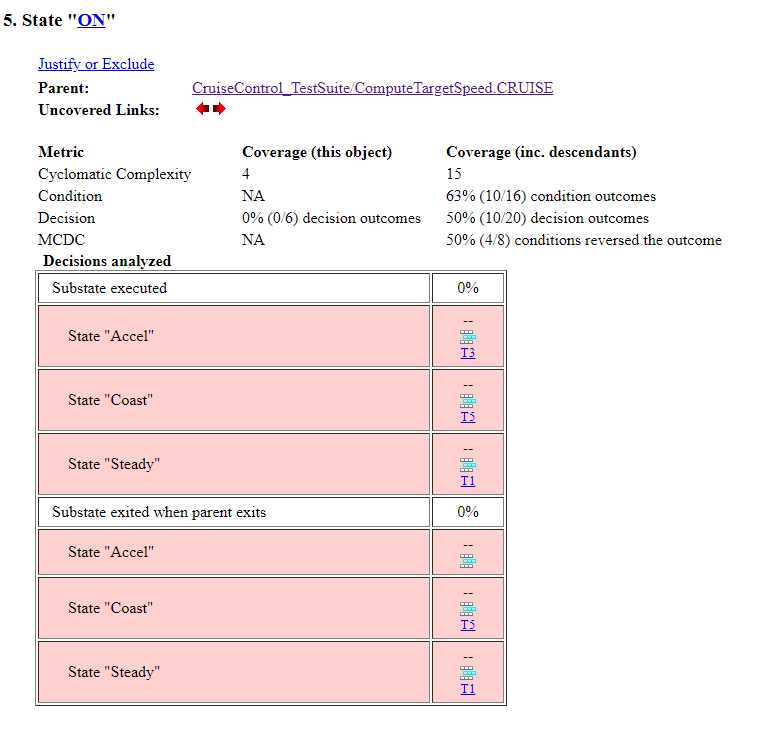

Notice how each coverage objective, though labeled as "missing" via red highlighting, also has an associated test case?

In addition, it appears that there are no requirements links for the "ON" state.

In the coverage report, just beneath the "ON" state, you can see an example of a "fully covered" objective:

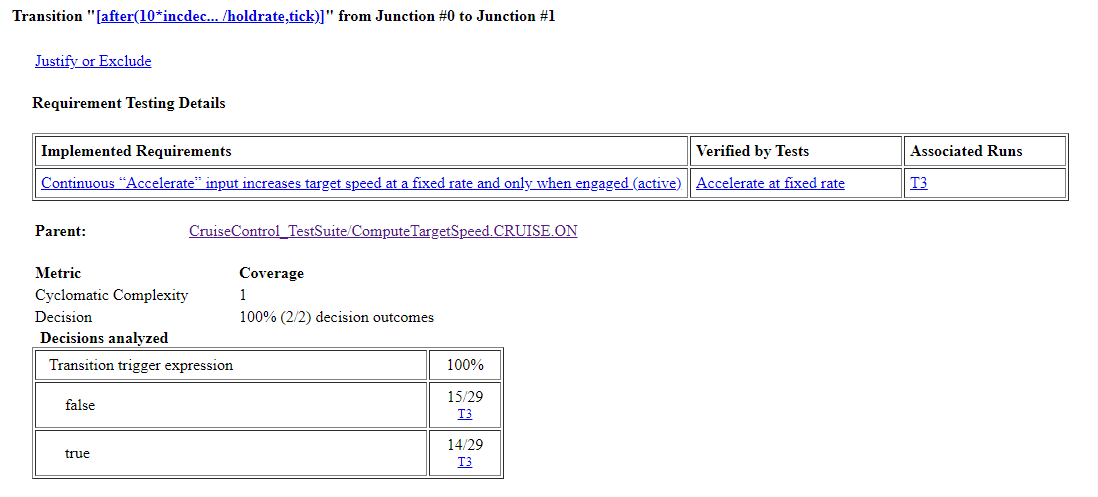

In this case, the Stateflow transition was fully exercised by test case T3, which also happens to be the test case associated with the parent requirement for the transition. In this case, the Stateflow transition has no "incidental" coverage.

## Step 5: Resolve Incidental Coverage

To resolve the issue with incidental coverage for the "ON" state, let's look at the requirements to determine whether we have a missing requirement or if the "ON" state implements an existing requirement (indicating incomplete traceability data).

1) Open the requirements set in the Requirements Editor:

slreq.clear
reqSet = 'CruiseControl_TestSuite.slreqx';
slreq.open(reqSet);
rmi.navigate('linktype_rmi_slreq',reqSet,'17')
clear reqSet

Requirement 2.4 seems to be the correct requirement to associate with this part of the design:

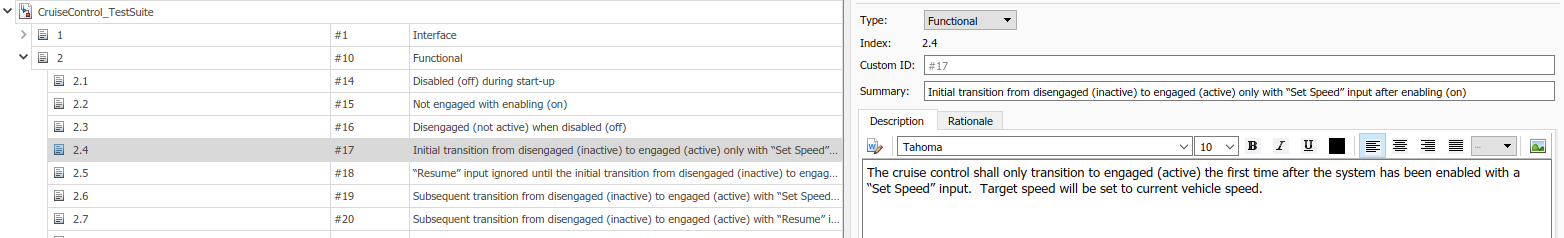

2) Create an "Implemented By" link from Requirement 2.4 to the "ON" state by selecting the requirement, then clicking **Add Link** in the Simulink Toolstrip, then "**Select for Linking with Requirement**."

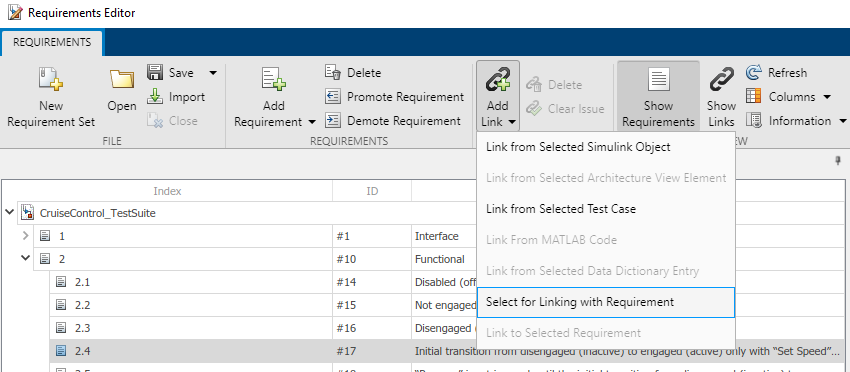

You can repeat this for other cases of "incidental coverage". 

**Tip**: You should analyze "requirements-scoped" coverage first, as it may indicate an issue with your requirements or test approach. One way to think about "requirements-scoped coverage" is a measure of how "effective" your tests are in efficiently verifying your requirements.

Let's now move on to missing model coverage due to incomplete testing.

## Step 6: Understand Incomplete Coverage By Generating Test Vectors

Recall that before we "scoped" coverage to requirements, we still had missing coverage. You can see this by going back to the Test Manager and unselecting "Scope coverage results to linked requirements".

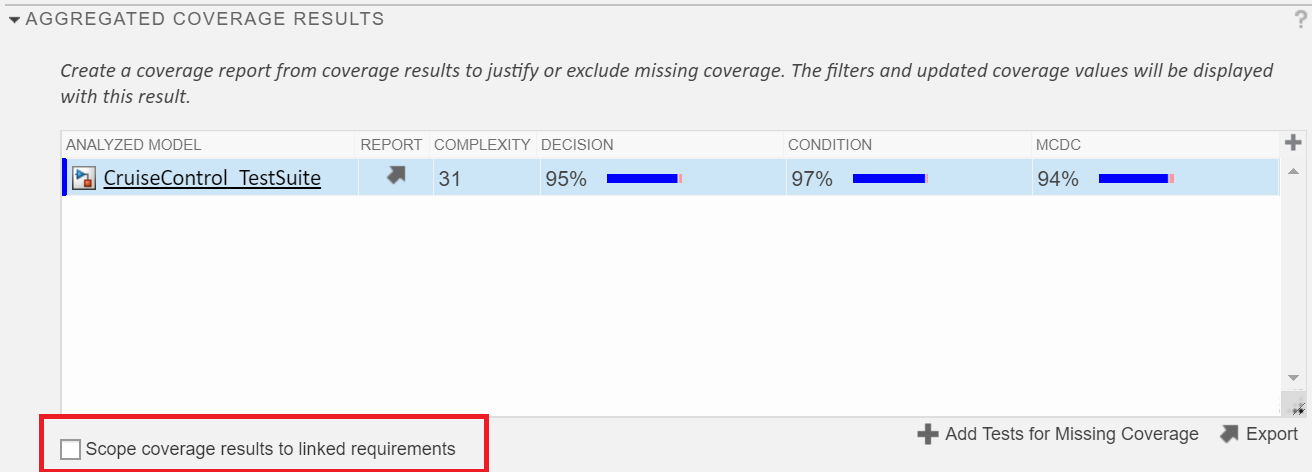

This missing coverage indicates that there were parts of your design which were not exercised during simulation.

1) Cick on the model name in AGGREGATED COVERAGE RESULTS

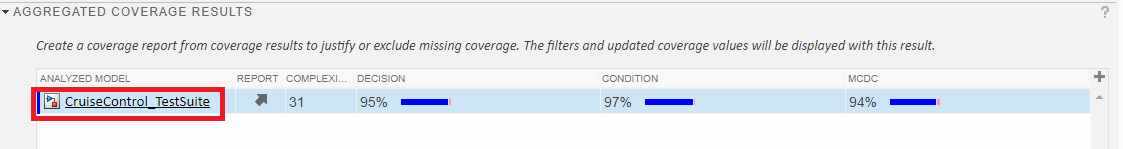

This will open the model with coverage results achieved when running the test suite.

The Coverage Details view allows you to see coverage results for model elements by clicking on them and viewing the details on a pane to the right of the Simulink canvas.

You can launch the Coverage Details view using the "badge" on the lower left of the Simulink canvas.

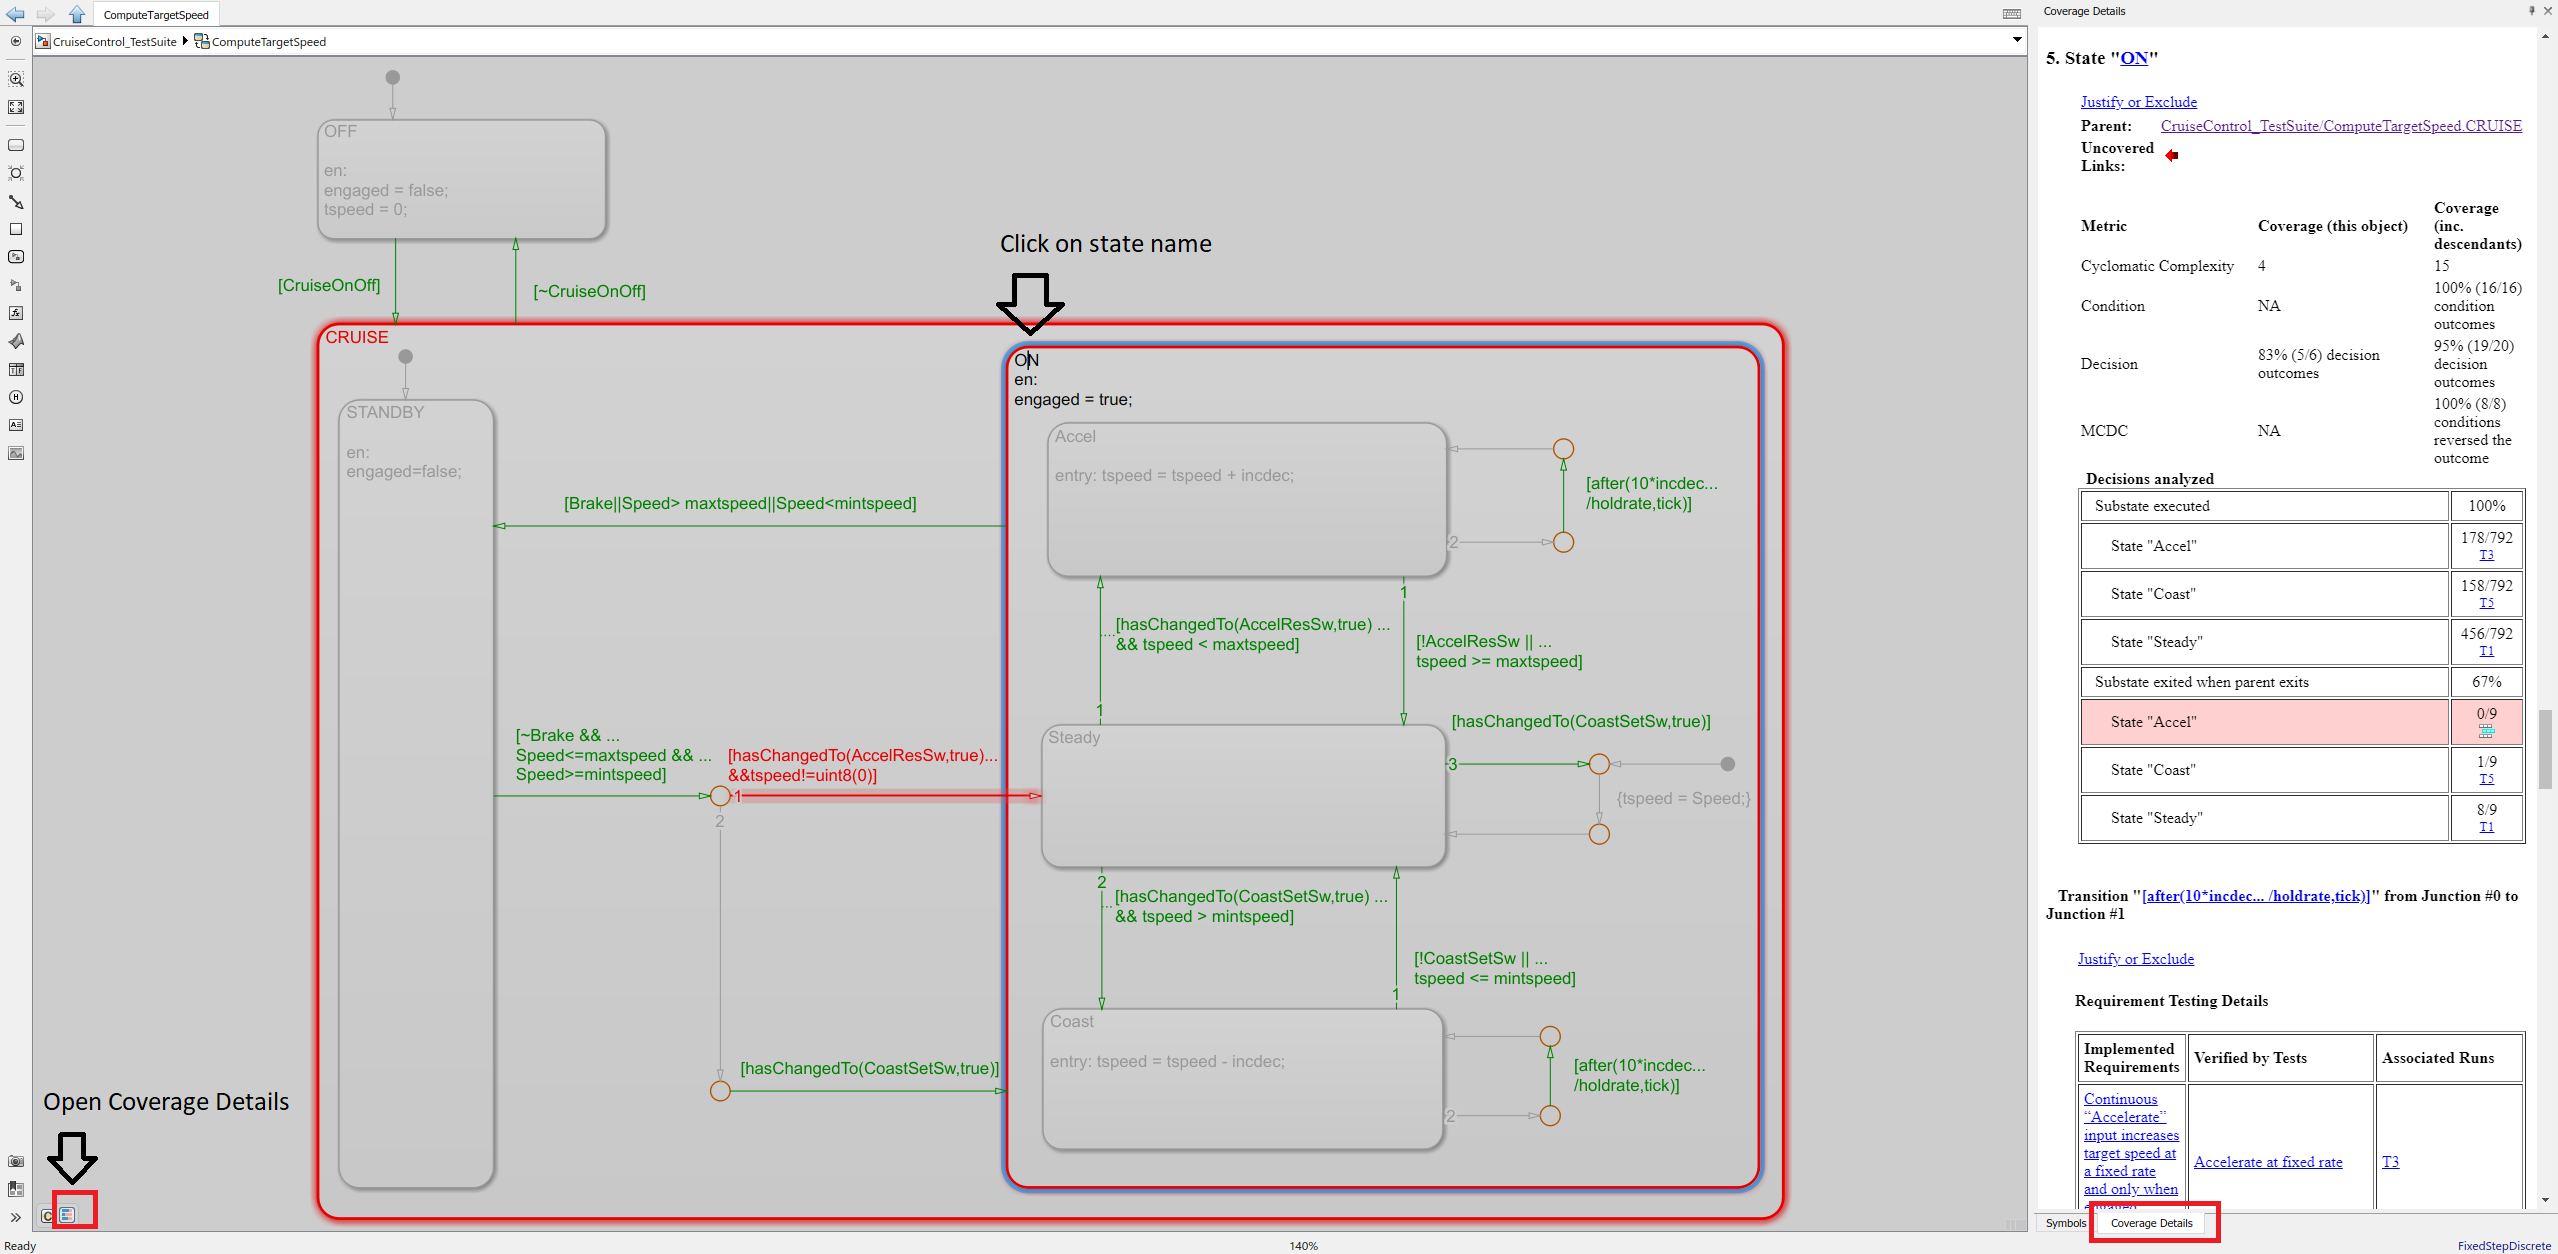

We'll come back to the missing coverage for the "ON" state soon.

#### **Causes for Missing Model Coverage**

There are many causes for missing model coverage, including dead logic, incomplete requirements-based tests, or missing or incomplete requirements.

In some cases, missing model coverage may be difficult to analyze due to design complexity. In these cases, automatically generated test vectors can help you understand what the simulation inputs would need to be in order to reach a given point in your design. These generated test vectors can also be used to supplement existing requirements-based tests.

Before we move forward, it is important to note that these automatically generated test vectors are not requirements-based because they do not include expected results, which you (the engineer) must define.

For this example, we will use Simulink® Design Verifier™ to automatically generate test vectors to analyze missing model coverage.

The two most important questions for this workflow are:

1) Is my design fully testable? In other words, is there dead logic? If a test cannot be generated to reach certain parts of your design, there might be dead logic in the design.

2) If my design is fully testable, what would a test cases look like? You can think of a test case as a "language" that can help you understand why you are missing test coverage in your requirements-based tests.

#### **Generate Test Vectors to Analyze Missing Model Coverage**

You can launch Simulink® Design Verifier™ directly from Simulink® Test™.

1) In the Results and Artifacts view in the Test Manager, click on the most recent test run

2) Under the AGGREGATED COVERAGE RESULTS section, select the most recent set of coverage results.

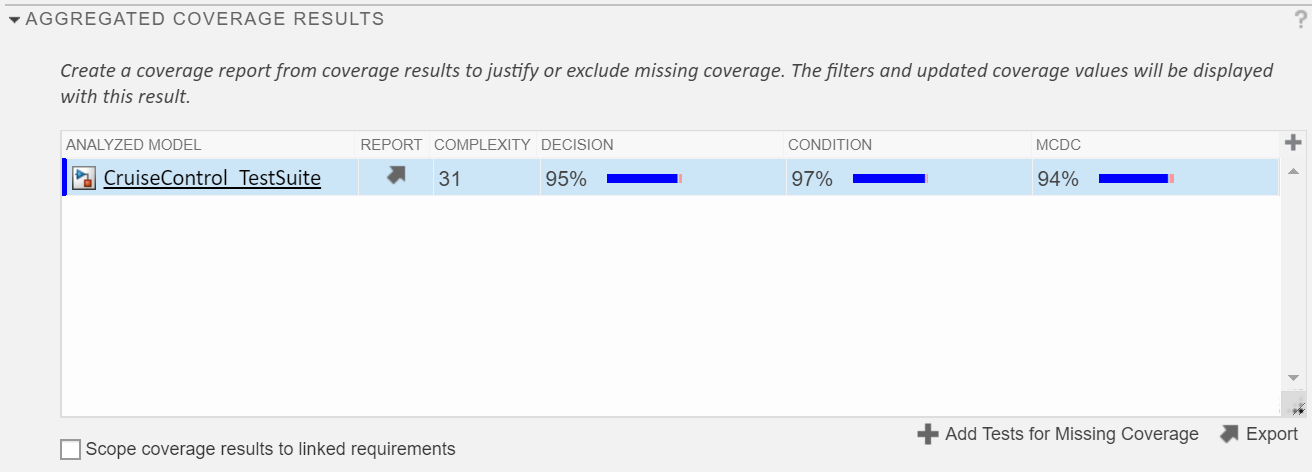

3) Click "Add Tests for Missing Coverage"

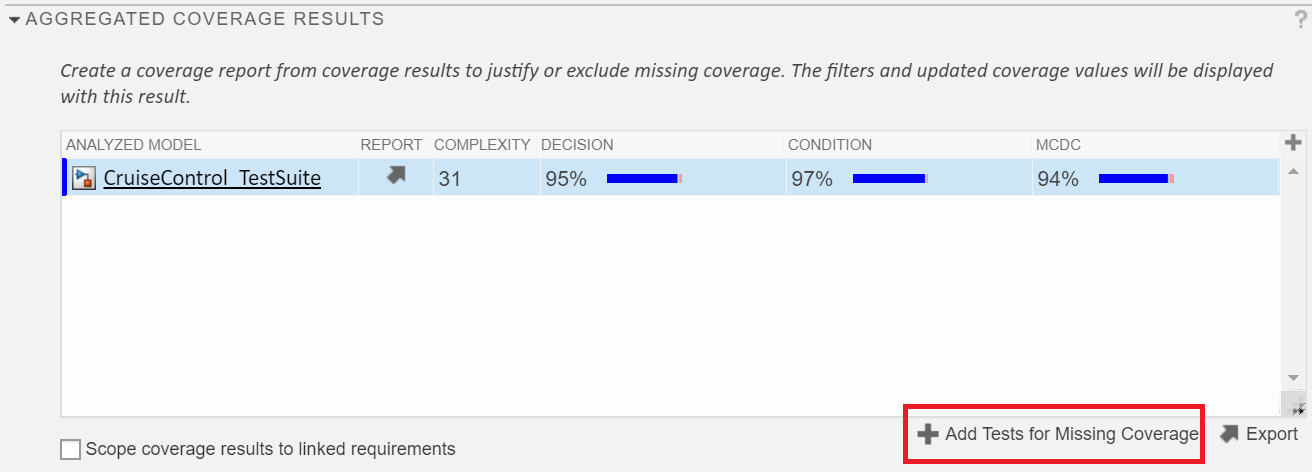

In the "Add Tests for Missing Coverage" pop-up, choose the following options:

1) **Harness**: <Create a new harness>

2) **Source**: Signal Editor

3) **Test Case**: <Create a new test case>

4) **Test Type**: Simulation Test

5) **Test File**: CruiseControl_TestSuite

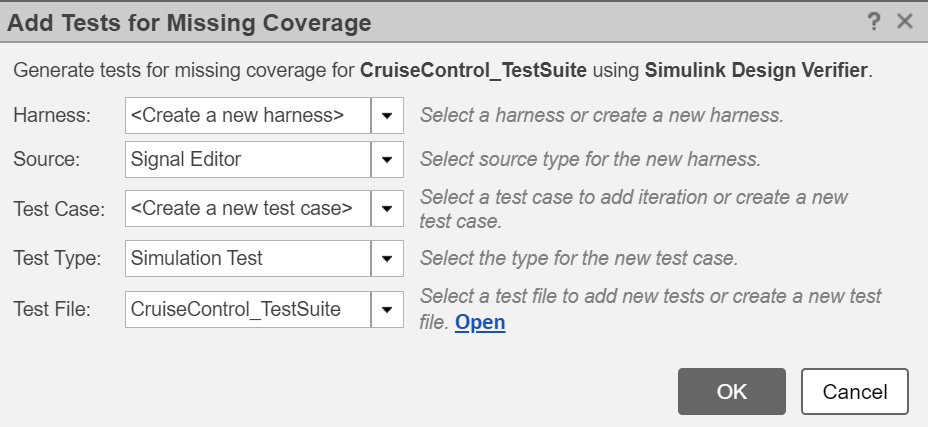

6) Click OK

Simulink® Design Verifier™ is then automatically launched with these settings. It will take into account the coverage achieved with the existing test cases, and will try to generate tests to fill in the remaining coverage.

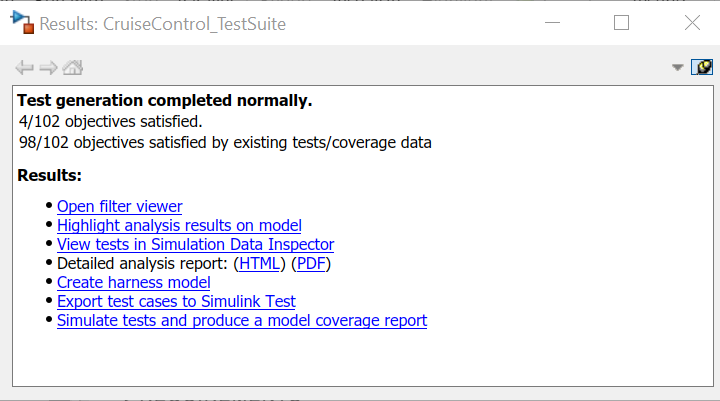

The Results window indicates that Simulink® Design Verifier™ has already accounted for the coverage achieved from the existing test cases, and generated test vectors to achieve coverage for four (4) coverage objectives.

Also note that all four objectives were satisfied, which indicates that these are not "dead logic." Though we did not show the workflow in this example, we recommend that you use Simulink® Design Verifier™ to check for the presence of dead logic before authoring tests. [Click here](https://www.mathworks.com/videos/how-to-use-simulink-design-verifier-to-automatically-detect-design-errors-in-your-simulink-models-1591187585343.html) to see a video on how to do this.

Once Simulink® Design Verifier™ has finished generating test vectors, the new test case will appear in the Test Manager:

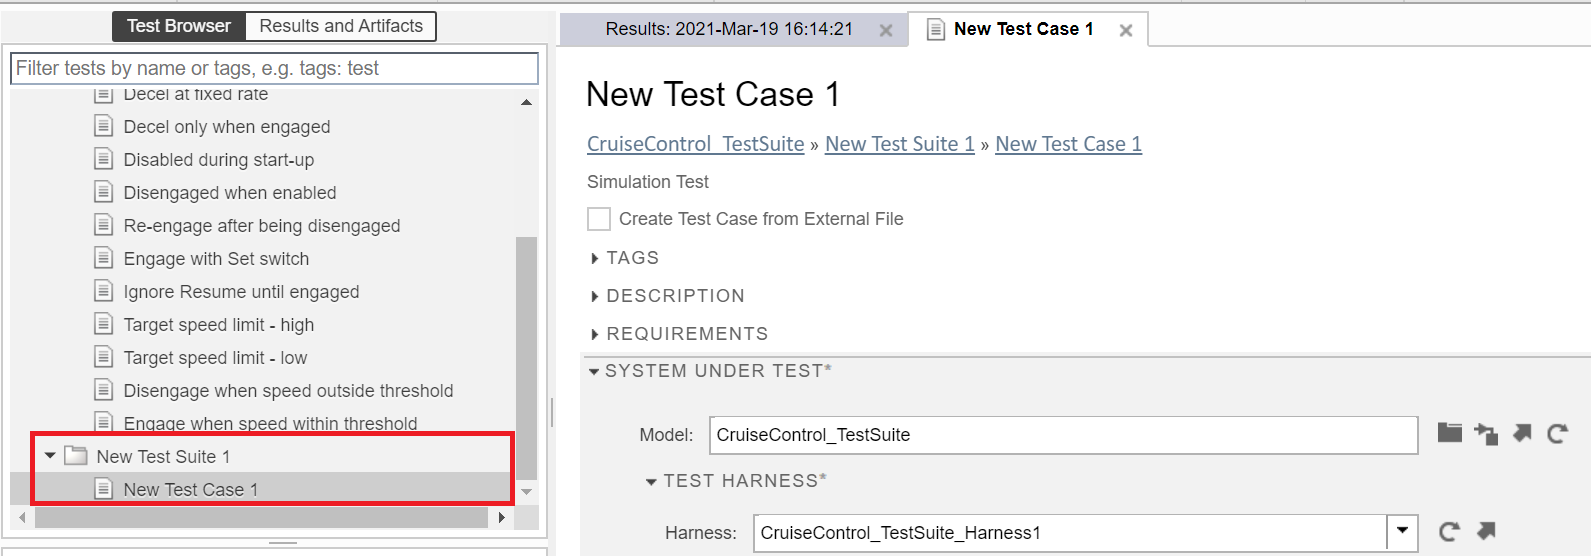

The three test vectors are iterations within that test case:

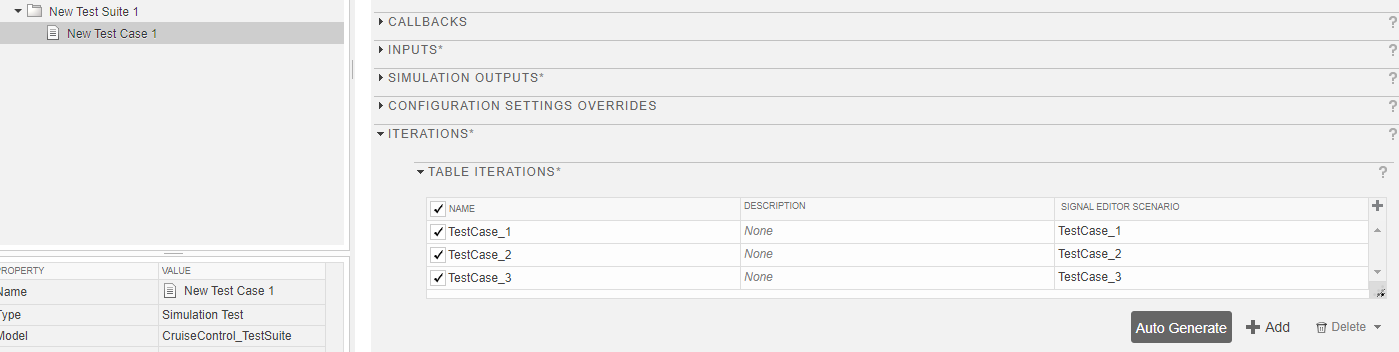

#### Generate Coverage Report for Full Test Suite with Automatically Generated Test Vectors

We could use this test case "as-is", but we want to understand how these test vectors help us achieve our coverage objectives for the entire test suite. We can do this by looking at the coverage report for the full test suite.

1) First, let's move this new test case into our existing test suite. You can do this by right clicking on the test case and selecting Cut, then Paste into the CruiseControl_TestSuite

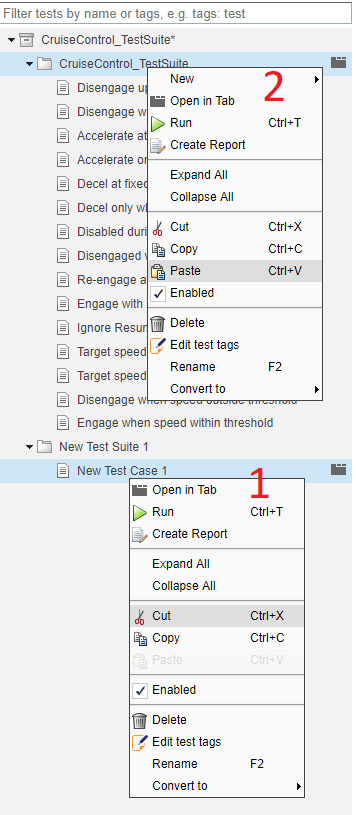

2) Rename the test case "Generated test vectors" for ease of reference

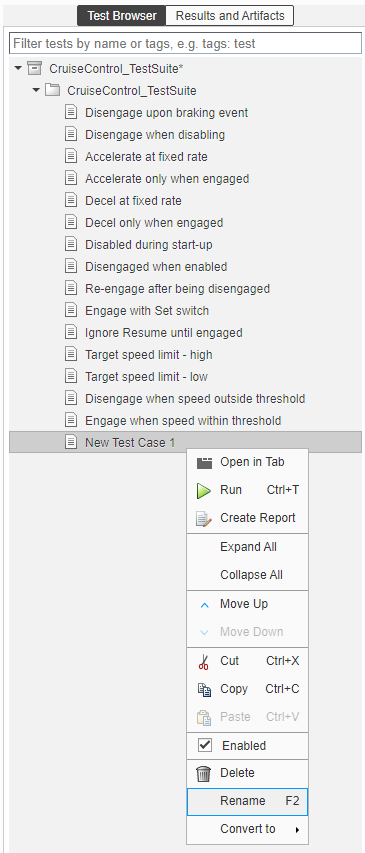

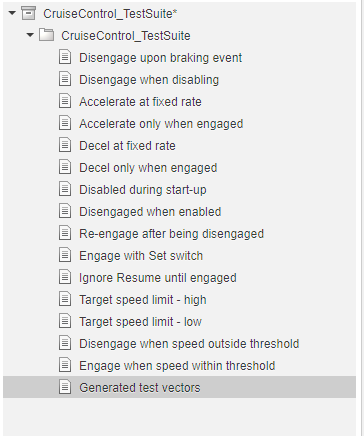

We need to be sure the Input data is logged when running this test.

3) In the INPUTS section of the "Generated test vectors" test case, select "Include input data in test result"

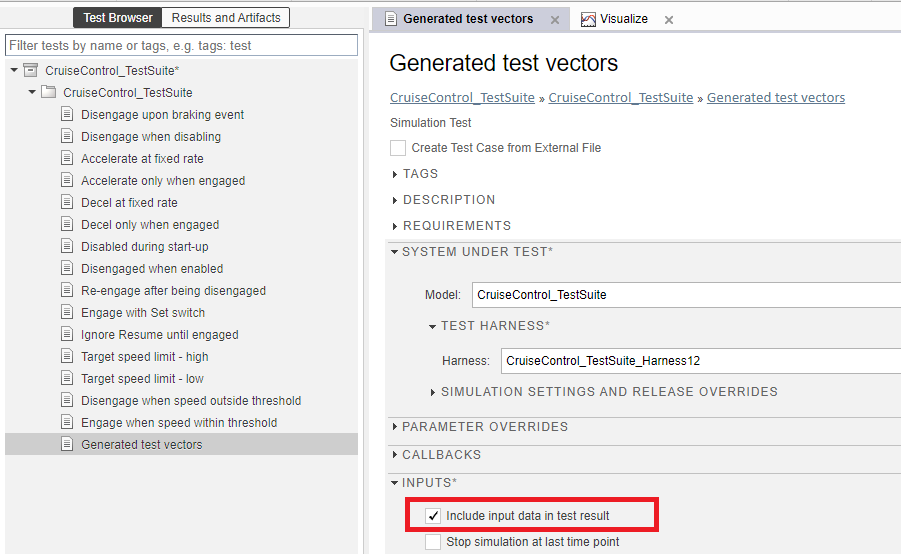

4) Run **CruiseControl_TestSuite** with the new test case.

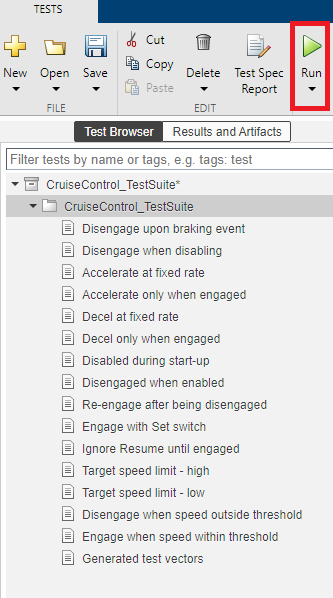

Here are the results:

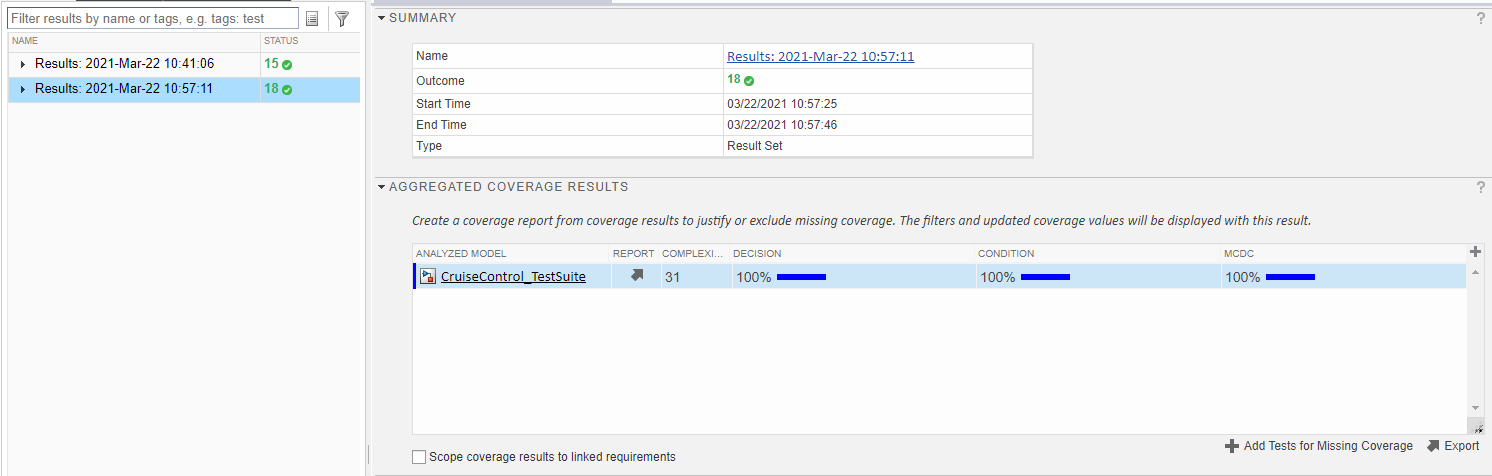

Notice that the summary of the test suite shows 18 tests have passed. This is expected: **there are no expected results for these new test vectors**. They are merely meant to help you analyze missing model coverage.

Let's generate a coverage report. This will help us understand which test case addressed each of the missing coverage objectives.

5) Click on the arrow icon in the Report column in the AGGREGATED COVERAGE RESULTS section.

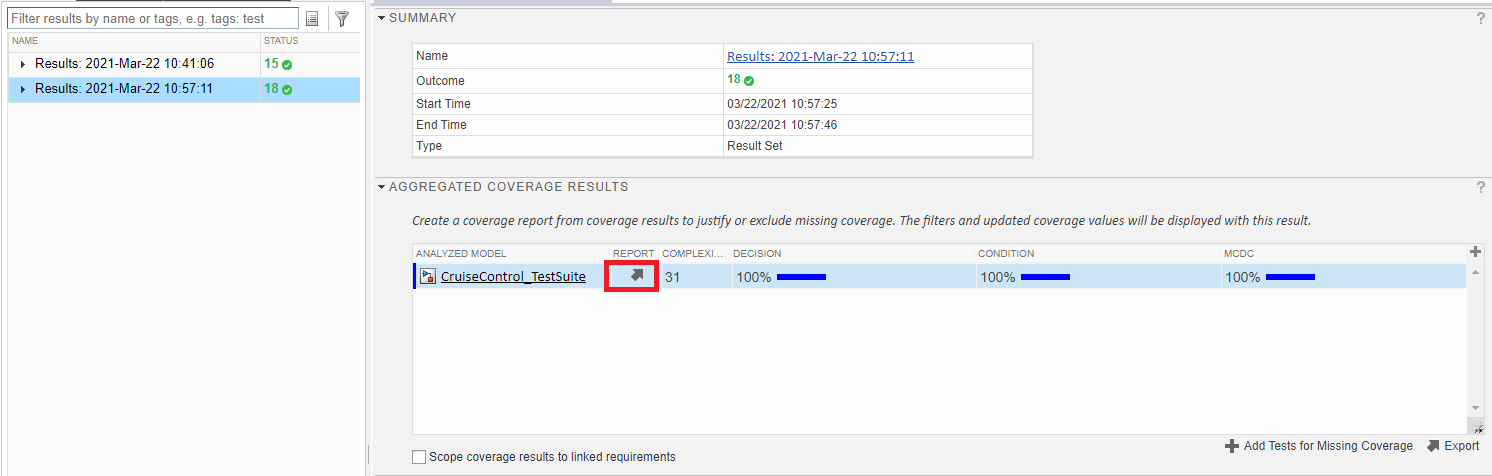

You will then see an HTML report showing the aggregated coverage.

Let's revisit the missing coverage from the "ON" state.

6) Click on the "SF: ON" hyperlink in the Summary section of the coverage report.

This will navigate to the section for the "ON" state:

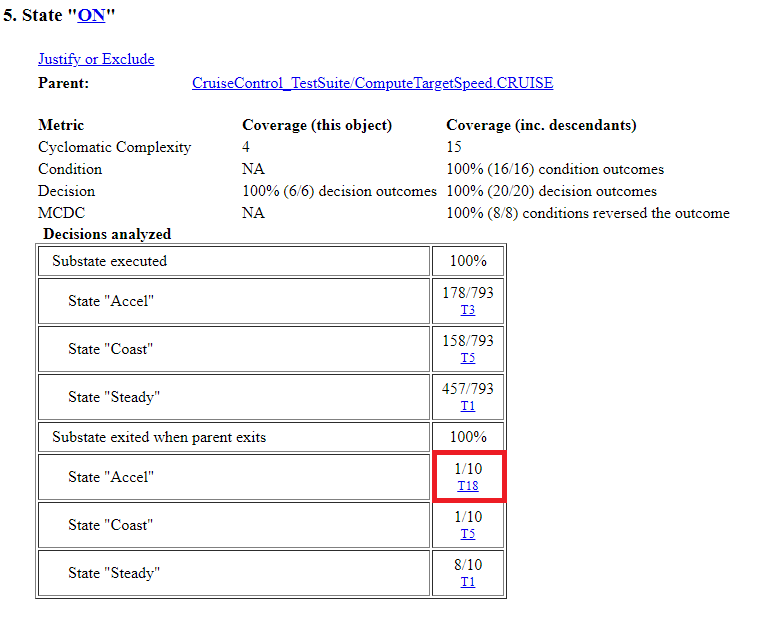

Recall that we are looking for a test case that would exit the ON state from the Accel substate. It looks like Test Case T18 did that. This was one of the automatically generated tests.

7) Click on the hyperlink "T18".

This will bring us up the list of the tests at the top of the report.

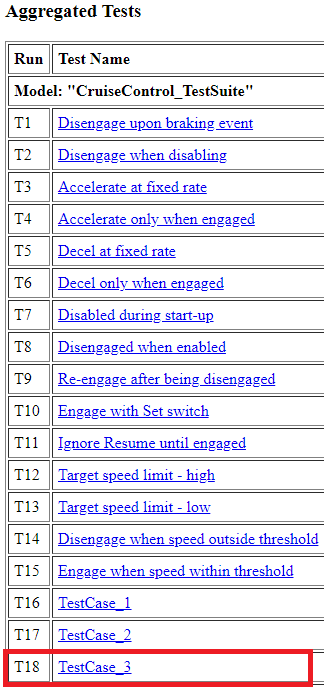

It looks like T18 is Test Case 3.

9) Click on the hyperlink "TestCase 3" to see the test case in Simulink® Test™.

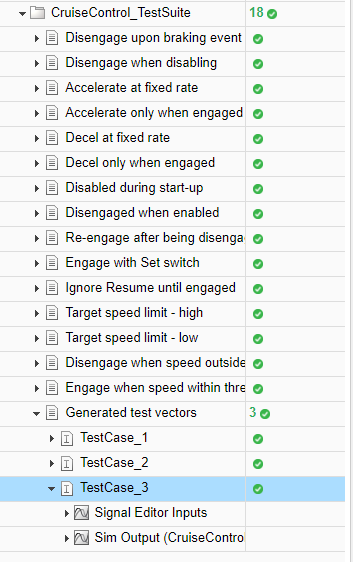

10) Visualize the test case. This can be done using the Visualize button in the toolstrip. Select "Show Simulation Output Plots".

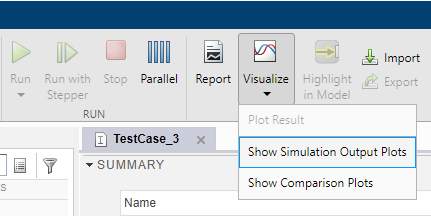

We can view the inputs by adding them via the Signal Editor Inputs dropdown. We can also add subplots using the Subplots 

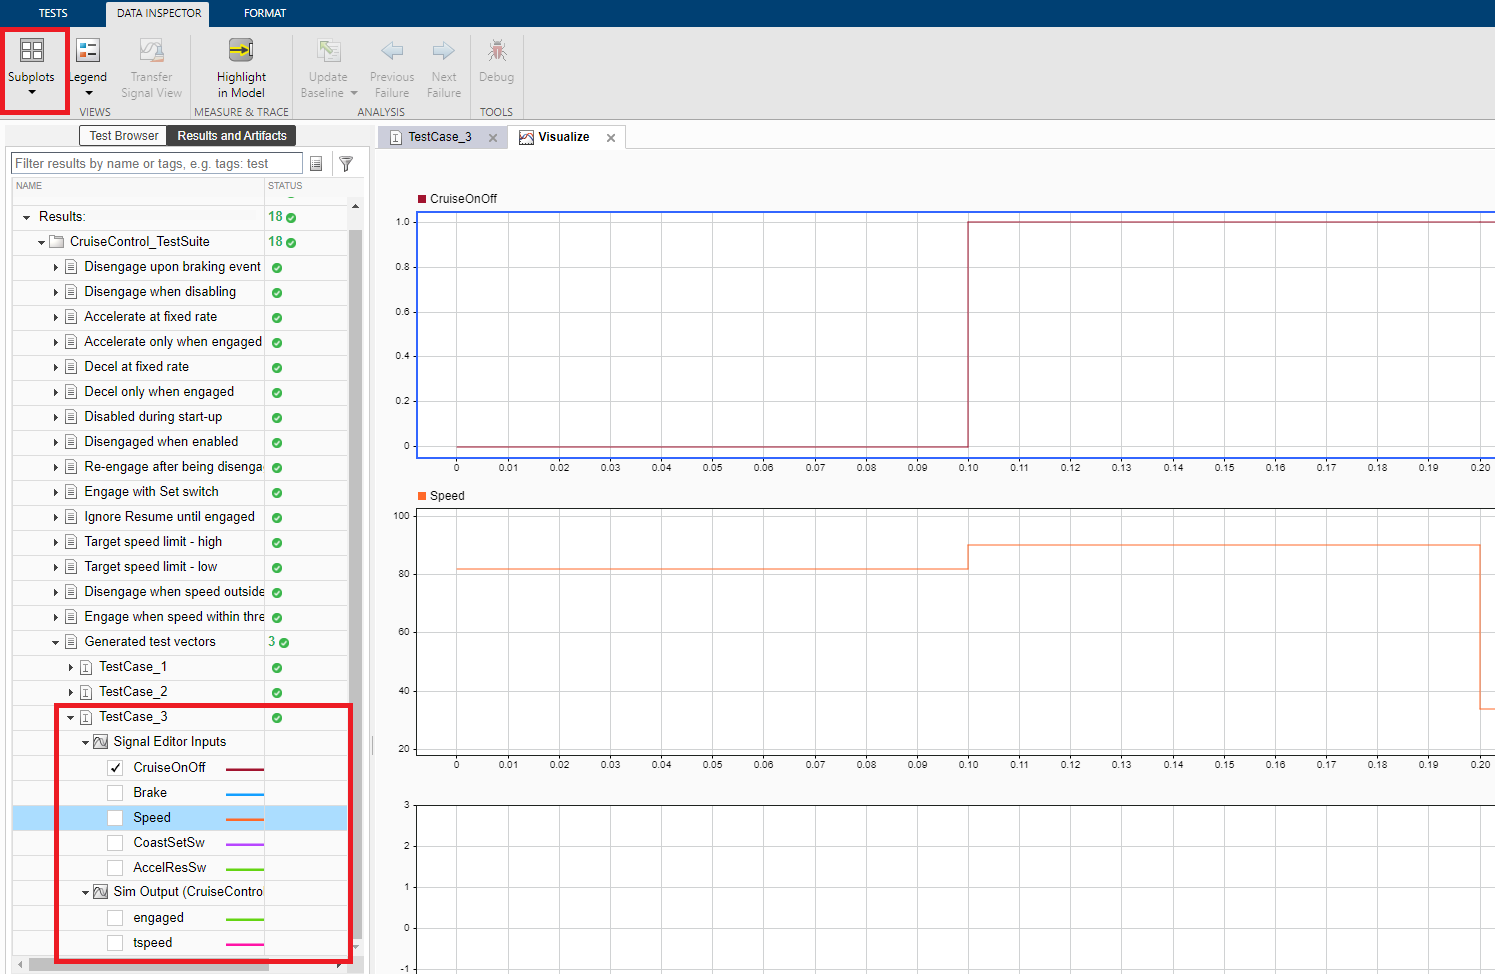

You can also "zoom" in on specific times and "pan" through the test case using your mouse.

By doing this, we can see how we would have achieved missing coverage.

The next step is to determine whether or not we should:

1) Write a new requirement

2) Modify an existing requirement

3) Append to or modify an existing test

4) Justify the missing coverage

In this case, the simplest option is #3: Append to or modify an existing test

In this case, we can simply append some additional steps to the **Disengage upon braking event** test case.

You can do this by opening the test harness using the arrow button in the Test Manager.

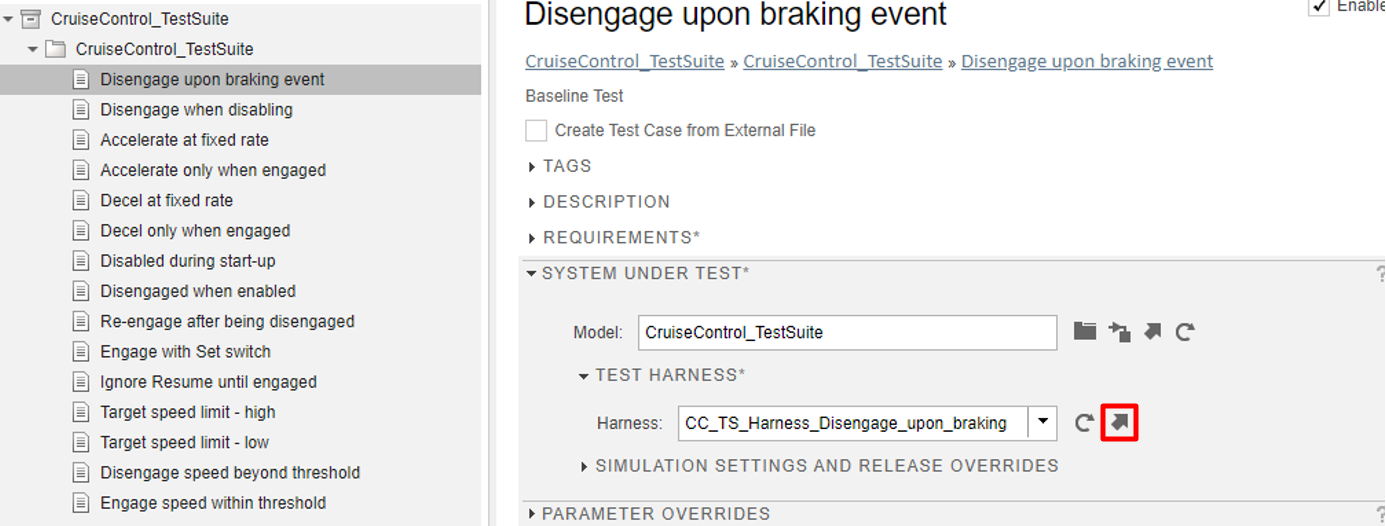

Try this yourself.

**Congratulations!** You have successfully tested the model and ensured complete test coverage. Simulink® Design Verifier™ includes several other features, such as design error detection and property proving. Be sure to [check out these other features](https://www.mathworks.com/products/simulink-design-verifier.html).

# Summary

In this example workflow, we:

- created a test harness

- authored a test case using a Test Sequence block

- created and executed test cases

- scoped test cases to requirements and resolved "incidental" coverage

- analyzed missing coverage by generating tests